# Map Structure and Visualization

This documentation contains two main chapters. The first chapter explains how the map is structured in MOBATSim and specifics related to the MOBATSim map format. In the second chapter, you can learn how to extend the map and convert it to other formats to open them in the Driving Scenario App and visualize the post-simulation logged data in 2D Bird's Eye View Simulink 3D Animation, or Unreal Engine.

# I. MOBATSim Map Structure

MOBATSim map information has a specific format that is designed to define straight and curved roads. Let's start by defining the nodes or sometimes referred to as waypoints. The MOBATSim coordinate system is first designed according to the Simulink 3D Animation. Therefore, the y-axis is used for the height and is always zero. This flat map limitation might be updated in the future.

## Straight Road Definition

A **waypoint** has the coordinate structure as $\left\lbrack \begin{array}{ccc}
x & 0 & -y
\end{array}\right\rbrack$.

A straight road defined between two waypoints is structured as below.

$\textrm{Straight}\;\textrm{Road}:=\left\lbrack \begin{array}{ccc}
x_s  & 0 & y_s \\
x_d  & 0 & y_d \\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$ for example: $\left\lbrack \begin{array}{ccc}
-200 & 0 & -300\\
-80 & 0 & -300\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$ is the **route** from waypoint **47** to **46**:

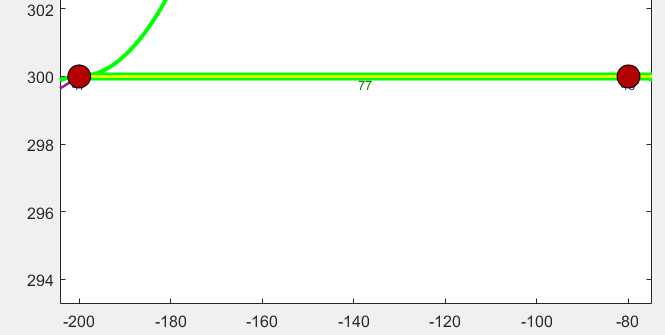

The third and fourth rows of zeros work as placeholders, as the curved roads contain the necessary information in these rows.

## Curved Road Definition

The curved roads in MOBATSim are defined as arcs which can be approximated as [osculating circles](https://en.wikipedia.org/wiki/Curvature#Osculating_circle). Therefore the [curvature](https://en.wikipedia.org/wiki/Curvature) is constant throughout the road segment, and each curved road segment is defined according to a starting point, endpoint, the center of rotation, and the sweeping angle.

A curved road defined between two waypoints is structured as below:

$\textrm{Curved}\;\textrm{Road}:=\left\lbrack \begin{array}{ccc}
x_s  & 0 & y_s \\
x_d  & 0 & y_d \\
\alpha_r  & x_r  & y_r \\
\pm 1 & \pm 1 & \pm 1
\end{array}\right\rbrack$for example: $\left\lbrack \begin{array}{ccc}
100 & 0 & -300\\
170 & 0 & -370\\
1\ldotp 5708 & 100 & -370\\
-1 & -1 & -1
\end{array}\right\rbrack$ is the curved **route** from waypoint **54** to **52**. 

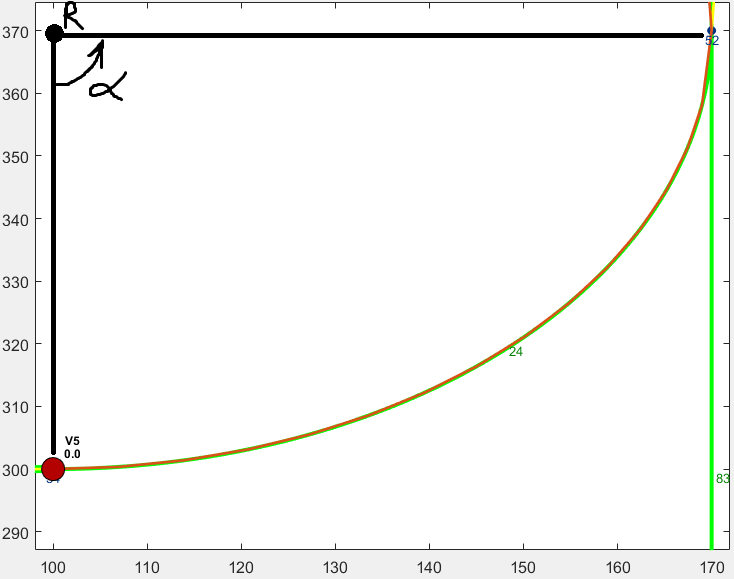

The difference between the coordinate systems is a known issue and will be resolved in a future update. For now, it should be noted that according to the figure below starting point at $\left\lbrack \begin{array}{cc}
100 & 300
\end{array}\right\rbrack$, destination $\left\lbrack \begin{array}{cc}
170 & 370
\end{array}\right\rbrack$ and the rotation center is located at $\left\lbrack \begin{array}{cc}
100 & 370
\end{array}\right\rbrack$. The rotation angle from the starting point to the destination point  is ($\frac{\pi }{2}=1\ldotp 5708$) with a constant radius $R$ value. Therefore the curvature value $\kappa$ is invariant for each curved road segment.


$$\kappa =\frac{1}{R}$$


So here 3rd row's 1st column shows the angle of the arc in radians; the rotation center is the point the radius of the arc is defined. 4th row is either -1 for a counterclockwise or +1 for a clockwise turn. This information is vital since all the routes in MOBATSim are one-way routes.

## Visualization Example

Here is an example code to run and visualize a small map. The road definitions are hard-coded below which are normally obtained all together when the map is loaded. The functions below will be explained in the next sections, therefore, only focus on the structures of the waypoints, circle connections and translation connections.

**map.connections.all: **This vector stores the connections inside the graph. First, all circles and then all translations are stored.

[start node , end node]

**map.connections.circles:** [start node , end node, angle, x , z ,y of center of the circle, speed limit]

**map.connections.translations:** [start node , end node, speed limit]

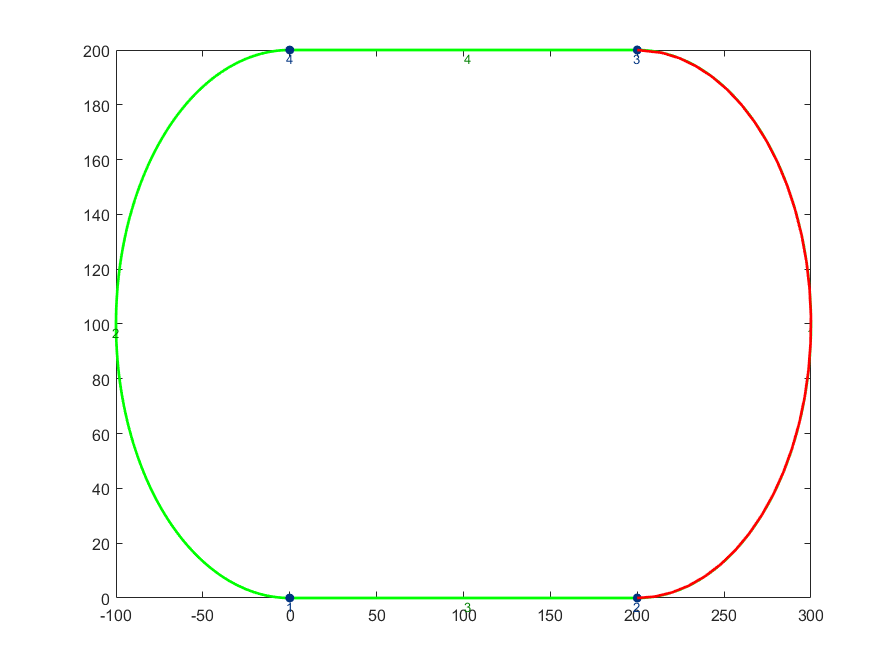

figure
%create struct as substitute for map
map = struct;

%                       x  z     y  Node
map.waypoints = [       0  0     0; %1
                      200  0     0; %2
                      200  0  -200; %3
                        0  0  -200];%4
                    
%                        start  goal  angle  x  z   y  speed
map.connections.circle = [ 2     3      pi  200 0 -100 20;
                           4     1      pi    0 0 -100 20];
%                             start goal speed                       
map.connections.translation = [ 1     2   20;
                                3     4   20];

displayInGridCoordinates = false;
generateMapVisual(map,displayInGridCoordinates);
%please only run until after the generateMapVisual function and return to
%here to see the plot

%plot path
carID = 1;
path = [1 2 3];
map.Vehicles(1).dynamics.position = [0 0 0];%the algorithm needs to know the current vehicle location

pathPlot = plotPath(map,path,carID);

delete(pathPlot);
map.Vehicles(1).dynamics.position = [200 0 0];
path = [2 3];
pathPlot = plotPath(map,path,carID);

## Loading and Generating the Map

In the main script, *prepare_simulator* is necessary to load and assign the simulation parameters. It also loads and creates the Map from the `GridMap` class. During the simulation runtime, the planned paths of the vehicles are plotted and highlighted dynamically with different colors. This enables the user to see the planned paths and also to realize if a replanning occurs and the vehicle changes its planned path.

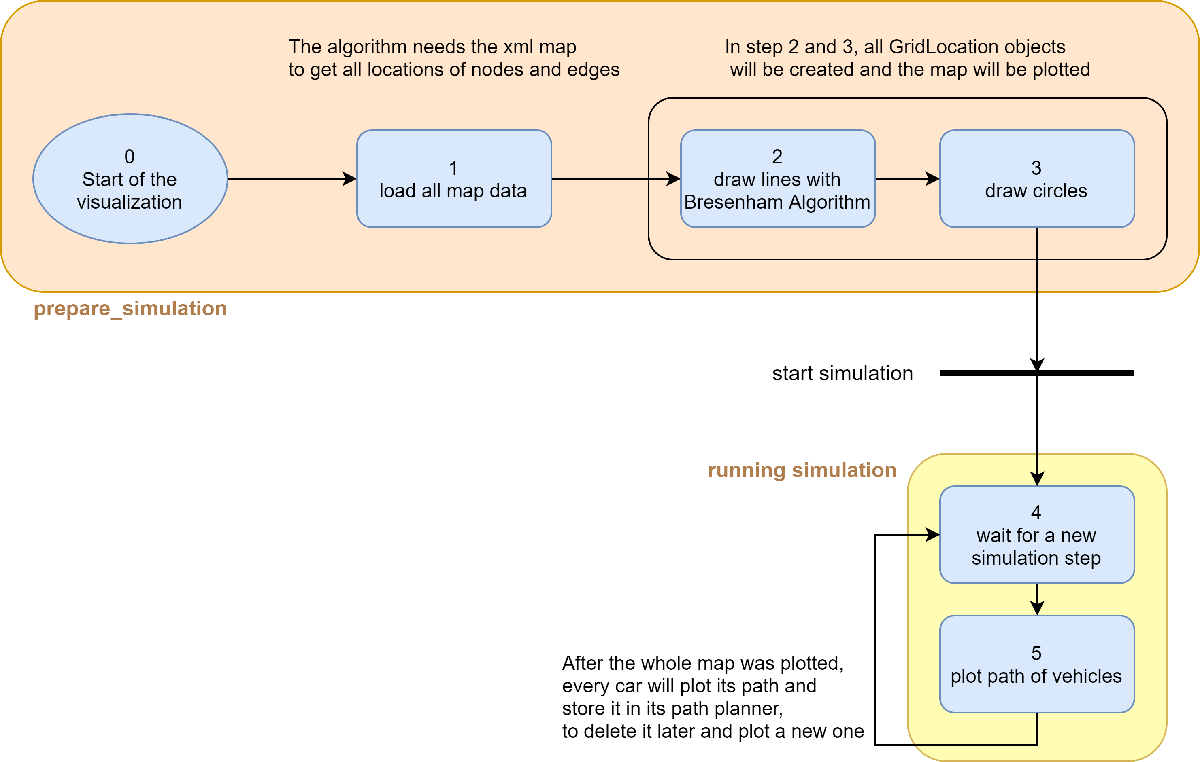

In **Step 1**, all needed data will be gathered. To be able to create a grid and plot everything at the right place, all matrices of the graph that contain information on the location and orientation of nodes and edges are needed. 

**Step 2** and **Step 3** will plot the map like the one that was shown in the previous example inside the `GridMap` class' constructor. This Map plot will stay, as the map does not change during the runtime. The vehicles and their planned paths will be plotted on top and will be updated during the simulation.

In **Step 4** and **Step 5**, the planned paths determined and stored inside the `VehiclePathPlanner` will be deleted and redrawn in every update cycle during the simulation.

### Loading the Map

The load function returns a set of necessary variables for the creation of the Map object later on. These variables include the waypoints, the connections between these waypoints, lane numbers of the routes, and intersection-related waypoint information.

When the load function (`load_Mobatkent_from_opendrive`) is called, the map structure has to be loaded from an existing `.mat` file, or if there are any new modifications to the map (for example, a set of new road segments are added using the **DrivingScenarioDesigner APP**), they need to be converted to the MOBATSim. The default value for the optional argument convert is `false`; therefore, it has to be run with true to convert the map from the OPENDrive Format to the MOBATSim Format.

In both cases, the information about the intersection nodes is not captured, so this information is hard-coded in the script. Details about the differences between the intersection management nodes (`startingNodes`, `brakingNodes`, `stoppingNodes`, `leavingNodes`) are explained in another documentation file.

The map conversion algorithm `map_extend_v1` is explained along with the other 3D visualization information in the next chapter.

### Creating the Map Object, 2D Plot and Planned Path Display

Once the required data about the Map is loaded, they are passed into the constructor function of the [GridMap class](matlab:open('..\src\Models and Classes\Maps\GridMap.m')) to create the Map instance in the `prepare_simulator` script.

The class *GridMap.m* includes the following functions: 

- generateMapVisual.m

- generateBOGrid.m

- GridLocation.m

**Warning:** Due to the last updates and optimizations, the functions below might be slightly different in the actual GridMap class. However, the fundamental working principles should be the same. You can use the plot example below in **debug mode** and the **step-in** button during the debugging session to go through the calculations below.

#### generateMapVisual()

The function generateMapVisual creates the map plot to see where vehicles are going.

 function generateMapVisual(obj,displayInGridCoordinates)

**Input:**        map object, boolean = 1 if we want use grid coordinates instead of normal ones

**Output:**     --

We start with `hold off` to start a new figure and then use `hold on`, to draw everything inside one plot. We also have to load every map information.

            hold off
            waypoints = obj.waypoints;
            circ = obj.connections.circle; %curves
            trans = obj.connections.translation; %straight roads
            % get the length of circ, trans and waypoints
            nrCurves = size(circ,1);
            nrStraights = size(trans,1);
            nrWaypoints = length(waypoints);
            %coordinate transformation
            waypoints(:,3) = -1.*waypoints(:,3);    %MOBATSim stores the negative y, so we have to transform it
            circ(:,6) = -1.*circ(:,6);

The function still has the option to switch to grid coordinates. This can not be used at the moment because the cars would have to change to grid position as well in the plot, but it could be used later on.

            if displayInGridCoordinates
                xOff = min(waypoints(:,1))-50;
                yOff = min(waypoints(:,3))-50;
                
                waypoints(:,3) = waypoints(:,3)-yOff;
                waypoints(:,1) = waypoints(:,1)-xOff;
                
                circ(:,4) = circ(:,4)-xOff;
                circ(:,6) = circ(:,6)-yOff;
            end         

We start with the curved roads. For every **curved road**, we load the starting and ending points and calculate the angles in between. Then we calculate **points on the circle** with this information and **plot the curve**.

            %% Generate a usable plot       
            %% generate curves        
            % preallocate array for all curve text positions
            textPosCurves = zeros(nrCurves,2);
            for c = 1 : nrCurves
                cPart = circ(c,:); %load information on the current curve
                %starting point
                x1 = waypoints(cPart(1),1);
                y1 = waypoints(cPart(1),3);
                %goal point
                x2 = waypoints(cPart(2),1);
                y2 = waypoints(cPart(2),3);
                %central point
                x0W = cPart(4);
                y0W = cPart(6);
                %radius
                radius = norm( [x2,y2]-[x0W,y0W] );
                %angles of start and goal
                phiStart = angle(complex((x1-x0W) , (y1-y0W)));
                phiGoal = angle(complex((x2-x0W) , (y2-y0W)));
                %direction
                direction = sign(cPart(3));
                %% make angle allways usable
                %we have to make every angle positive and also big eneough,
                %that an angle of a point is allways between start and goal
                if phiStart <0
                    phiStart = phiStart + 2*3.1415;
                end
                if phiGoal <0
                    phiGoal = phiGoal + 2*3.1415;
                end
                %make turns through 0° possible
                if (direction == -1 && phiStart < phiGoal)
                    phiStart = phiStart + 2*3.1415;
                end
                if (direction == 1 && phiStart > phiGoal)
                    phiGoal = phiGoal + 2*3.1415;
                end

A vector with some angles is created to calculate points on the circle to plot later.

                %create an array with all angles between start and goal
                phi1 = phiStart : direction*0.01 : phiGoal;
                %set first and last, to make shure there are no gaps in the
                %plot because of rounding errors
                phi1(1) = phiStart;
                phi1(end) = phiGoal;
                %create the points to plot from angle and radius
                points = [(radius .* cos(phi1)+x0W)',(radius .* sin(phi1))'+y0W];               

Now the whole circle segment is plotted.

                if c ==1
                    hold off
                else
                    hold on
                end
                %plot it
                plot(points(:,1),points(:,2),'color',[0 1 0],'LineWidth',2);
                % save text position in array
                textPosCurves(c,:) = points(round(length(points)/2,0),:);
            end
             %plot text next to curve
            text(textPosCurves(:,1),textPosCurves(:,2),num2str((1:nrCurves)'),'color',[0 0.5 0], ...
                                                                              'VerticalAlignment','top', ...
                                                                              'HorizontalAlignment','center');

We only need to plot a line between the start and the goal point for the **straight lines**.

We also add the number of the edge as a description.

            %% generate straight lines
            
            % x positions of start and end of straight roads
            xPositions(:,:) = [waypoints(trans(:,1),1) ,waypoints(trans(:,2),1)];
            % y positions of start and end of straight roads
            yPositions(:,:) = [waypoints(trans(:,1),3) ,waypoints(trans(:,2),3)];
            % plot all straight roads
            plot(xPositions',yPositions','color',[0 1 0],'LineWidth',2);
            
            % position text at the middle of the straight road
            textPosX = (xPositions(:,2) + xPositions(:,1))/2;
            textPosY = (yPositions(:,2) + yPositions(:,1))/2;
            % plot text next to straight roads
            text(textPosX,textPosY,num2str((nrCurves+1:nrCurves+nrStraights)'),'color',[0 0.5 0], ...
                                                                               'VerticalAlignment','top', ...
                                                                               'HorizontalAlignment','left');         

The last thing would be to plot the nodes with their number.

            %% plot nodes with numbers
            % 2D positions
            pos = [waypoints(:,1),waypoints(:,3)];
            %plot dot and number in a dark blue
            plot(pos(:,1),pos(:,2),'Marker','o','MarkerFaceColor',[0 0.2 0.5],'color',[0 0.2 0.5],'LineStyle','none');
            % plot number next to waypoints           
            text(pos(:,1),pos(:,2),num2str((1:nrWaypoints)'),'color',[0 0.2 0.5], ...
                                                             'HorizontalAlignment','center', ...
                                                             'VerticalAlignment','top');
            hold off
         end

[Back to plot]

#### generateBOGrid()

This function generates the **Binary Occupancy Grid (BOG)** object and a GridLocation object for every cell in the BOG.

            function [bogMap,xOff,yOff] = generateBOGrid(map)

**Input:** GridMap object

**Output:** the bog object, the x offset, the y offset of the bog map

First, we start by importing every map data.

            %% prepare for drawing
            nrOfCars = length([map.Vehicles.id]); %comment in if you know
            %the number of cars            
            gRes = map.gridResolution;
            %first we need map size
            %we can get it from waypoints with some space for better
            %display
            distances = map.connections.distances;
            w = map.waypoints;  %[x z y]
            w(:,3) = -1.*w(:,3);%transform to mobatsim coordinates

We need to determine the size of the map here.

            xSize = max(w(:,1))-min(w(:,1))+100;
            xOff = min(w(:,1))-50;            
            ySize = max(w(:,3))-min(w(:,3))+100;
            yOff = min(w(:,3))-50;

The speed limit has to be accurate for every vehicle.

            %calculate speedLimit [carID,edgeNR]
            maxEdgeSpeed = [map.connections.circle(:,end);map.connections.translation(:,end)];
            speedLimit = zeros(nrOfCars,length(maxEdgeSpeed));
            for car = 1 : nrOfCars
                maxSpeed = map.Vehicles(car).dynamics.maxSpeed ;
                maxEdgeSpeed(maxEdgeSpeed>maxSpeed)= maxSpeed;
                speedLimit(car,:) = maxEdgeSpeed;
            end             

Now we can create the BOG object and start with the map generation. The cars can only use the edges, so the rest has to be blocked.

            bogMap = binaryOccupancyMap(xSize,ySize,gRes);
            %mark everything as blocked
            occ = ones(ySize*gRes,xSize*gRes);
            setOccupancy(bogMap,[0,0],occ);%lower left corner to set values
            
            %import map details
            trans = map.connections.translation; %[from to speed]
            circ = map.connections.circle; %[from to angle xzyCenter speed]
            circ(:,6) = -1.*circ(:,6);

To create straight edges, we use [Bresenham's line algorithm](https://en.wikipedia.org/wiki/Bresenham%27s_line_algorithm).

Bresenham's line algorithm moves one step closer to the longer distance (in $x$ or $y$) in every iteration. It uses an error term to measure if it has moved too far away from the original line, and by that, it has to go diagonal in $x$ and $y$.

The error starts at half the longer distance, and with every step, the shorter distance will be subtracted. If the result is negative, we have to go diagonal. A longer distance will be added to the negative result to initialize a new error.

Example: We have `deltaX=9` and `deltaY=3`. The initial error would be half the longer distance, 4.5. The first step would have an error of 4.5 - `deltaY=1.5`. Because it is positive, we can stay in that row and go only in x-direction. The second step has an error of `1.5-3=-1.5`, so it is negative, and by that, we have moved too far from the original line. This is corrected by moving both in x and y one step from `(2,1)` to `(3,3)`. This procedure will continue until we reach the final pixel.

            %% bresenham algorithm
            for j = size(map.connections.all,1) :-1: (size(circ,1)+1)
                %% for each straight edge
                %conncetions.all stores first all circles, then all translations
                

`j` is the global number of that edge

`t` is the id of that edge inside the translation vector `trans`

                t= j - size(circ,1);
                dist = distances(j);
                %start node coordinates in grid
                p1 = bogMap.world2grid([waypoints(trans(t,1),1)-xOff,waypoints(trans(t,1),3)-yOff]);
                %end node coordinates in grid
                p2 = bogMap.world2grid([waypoints(trans(t,2),1)-xOff,waypoints(trans(t,2),3)-yOff]);
                %get difference
                deltaX = p2(1)-p1(1);
                delatY = p2(2)-p1(2);
                %get distance and direction
                absDx = abs(deltaX);
                absDy = abs(delatY); % distance
                signDx = sign(deltaX);
                signDy = sign(delatY); % direction

Here we set the step variables just to add the right amount to go to the next pixel.

                %determine which direction to go
                if absDx > absDy
                    % y is shorter
                    pdx = signDx;
                    pdy = 0;        %p is parallel
                    ddx = signDx;
                    ddy = signDy; % d is diagonal
                    deltaShortDirection  = absDy;
                    deltaLongDirection  = absDx;
                else
                    % x is shorter
                    pdx = 0;
                    pdy = signDy; % p is parallel
                    ddx = signDx;
                    ddy = signDy; % d is diagonal
                    deltaShortDirection  = absDx;
                    deltaLongDirection  = absDy;
                end

Starting to draw: Go to the next pixel and add the key to the pixel array.

                %start at node 1
                x = p1(1);
                y = p1(2);
                pixelArray = append(num2str(x), ",", num2str(y));                
                error = deltaLongDirection/2;                
                %% now set the pixel
                for i= 1:deltaLongDirection          
                    %% for each pixel
                    % update error
                    error = error - deltaShortDirection;
                    if error < 0
                        error = error + deltaLongDirection; % error is never < 0
                        % go in both direction
                        x = x + ddx;
                        y = y + ddy; % diagonal                        
                    else
                        % go in long direction
                        x = x + pdx;
                        y = y + pdy; % parallel
                    end   

Construct the key and add it to the array.

                    curKey = append(num2str(x), ",", num2str(y));
                    pixelArray = [pixelArray,curKey];
                end 

After all the pixels are gathered, they will be set by that function.

                %% now assign properties
                bogMap = setPixelFromArray(map,bogMap,dist,pixelArray,speedLimit(:,j),map.connections.all(j,1),map.connections.all(j,2),nrOfCars,j);
            end                  

The **second part** is for curved roads.

The pixel drawing algorithm searches for the neighbor with an angle between the current and goal angle. That pixel will be the next until the circle is completed.

            %% draw a circle pixel by pixel
            for t = size(circ,1):-1:1
                % t = nr of edge
                %% load information
                dist = distances(t);
                %starting point
                pStart = bogMap.world2grid([waypoints(circ(t,1),1)-xOff,waypoints(circ(t,1),3)-yOff]);
                %goal point
                pGoal = bogMap.world2grid([waypoints(circ(t,2),1)-xOff,waypoints(circ(t,2),3)-yOff]);
                %central point
                pCenter = bogMap.world2grid([circ(t,4)-xOff,circ(t,6)-yOff]); 
                
                radius = round(norm( pGoal-pCenter  ),0);
                phiStart = angle(complex((pStart(1)-pCenter(1)) , (pStart(2)-pCenter(2))));
                phiGoal = angle(complex((pGoal(1)-pCenter(1)) , (pGoal(2)-pCenter(2))));
                direction = sign(circ(t,3));                
                % make angle allways usable
                if phiStart <0
                    phiStart = phiStart + 2*3.1415;
                end
                if phiGoal <0
                    phiGoal = phiGoal + 2*3.1415;
                end
                offset = 0;
                %make turns through 0° possible
                if (direction == -1 && phiStart < phiGoal)
                    offset = 2*3.1415;
                    phiStart = phiStart + offset;
                end
                if (direction == 1 && phiStart > phiGoal)
                    offset = 2*3.1415;
                    phiGoal = phiGoal + offset;
                end  

All the pixels are gathered with the `calculateCircle()` function and then they are set and stored.

                %% calculate all pixel
                pixelArray = calculateCircle(pStart,phiStart,pGoal,phiGoal,pCenter,direction,radius,offset);
                %% now draw pixel and assign to map
                bogMap = setPixelFromArray(map,bogMap,dist,pixelArray,speedLimit(:,t),map.connections.all(t,1),map.connections.all(t,2),nrOfCars,t);
            end          
         end

#### setPixelFromArray

`SetPixel` creates a `GridLocation` object for every grid cell and sets the grid's occupancy value to `1` (free).

**Input:** All needed variables from generateBOG

**Output:** The altered binary occupancy map

function bogMap = setPixelFromArray(map,bogMap,dist,pixelArray,speedLimit,startNodeNR,endNodeNR,nrOfCars,edgeNumber)
    %get number of starting node and end node, to set unique
    %successors and predecessors per different edge    

Set the first GridLocation.

    curKey = pixelArray(1);
    %calculate distance of every cell
    dist = dist/size(pixelArray,2);
    %load or create GridLocation for starting node
    pStart = str2num(pixelArray(1));
    if ~map.gridLocationMap.isKey(curKey)
        curGL = GridLocation(pStart,nrOfCars,startNodeNR,0);
    else
        curGL = map.gridLocationMap(curKey);
    end
    %assign property
    curGL = curGL.assignDistance(dist);
    curGL.speedLimit = speedLimit;
    p = str2num(pixelArray(1));
    %set pixel
    setOccupancy(bogMap,p,0,"grid");

Now, all the cells which do not belong to any node but only to the edges are set.

    %% set all GridLocation objects on the road and connect them
    for s = 2 : (length(pixelArray)-1)
        %% start connecting
        % create new key
        newKey = pixelArray(s);
        % set pixel at location p
        p = str2num(newKey);
        setOccupancy(bogMap,p,0,"grid");
        %create new GL
        if ~map.gridLocationMap.isKey(newKey)
            newGL = GridLocation(p,nrOfCars,0,edgeNumber);
        else
            %or load old one
            newGL = map.gridLocationMap(newKey);
        end
        %% assign properties
        newGL = newGL.assignDistance(dist);
        curGL.speedLimit = speedLimit;
        %% assign successor and predecessor
        curGL = curGL.addTransSucc(newKey,startNodeNR);
        newGL = newGL.addTransPred(curKey,endNodeNR);
        %store in map
        map.gridLocationMap(curKey)=curGL;
        %% move to next GL
        curGL = newGL;
        oldKey = curKey;
        curKey = newKey;
    end

The last pixel is set separately because the last cell has no successor.

    %% set the last GL
    %get key
    newKey = pixelArray(end);
    if ~map.gridLocationMap.isKey(newKey)
        %create new
        p = str2num(newKey);
        newGL = GridLocation(p,nrOfCars,endNodeNR,0);
    else
        %load from map
        newGL = map.gridLocationMap(newKey);
    end
    %set inside bog
    setOccupancy(bogMap,p,0,"grid");
    p = str2num(oldKey);
    setOccupancy(bogMap,p,0,"grid");
    %assign properties
    newGL = newGL.assignDistance(dist);
    newGL.speedLimit = speedLimit;
    %assign succ and pred
    curGL = curGL.addTransSucc(newKey,startNodeNR);
    newGL = newGL.addTransPred(curKey,endNodeNR);
    %store inside map
    map.gridLocationMap(curKey)=curGL;
    map.gridLocationMap(newKey)=newGL;
    end    

#### calculateCircle

This algorithm calculates all the cells that belong to a curve and returns it as a vector.

**Input:** Points with angles, the direction of the circle in radiant, radius, and offset of the angle, if we pushed everything $2\pi$ to avoid going through 0°.

function pixelArray = calculateCircle(pStart,phiStart,pGoal,phiGoal,pCenter,direction,radius,offset)

    %start with the first one
    curPix = pStart;
    %assign it to an array
    pixelArray = [];%store points here
    pixelArray = [pixelArray,append(num2str(curPix(1)), ",", num2str(curPix(2)))];
    curPhi = phiStart;
    while curPix(1) ~= pGoal(1) || curPix(2) ~= pGoal(2)
        %while the goal pixel is not reached, go to the next
        %pixel, that is between the last one and the goal and
        %is closest to the radius
        nextPix = [];   %the next pixel to draw in grid
        nextPhi = 0;
        deltaR = 200000;     %set up distance to the radius point with angle phi to be allways higher first try
        %for every neighbour
        for x = -1 : 1
            for y = -1 : 1
                if x ~= 0 || y ~= 0
                    %compare pixel to get the closest one to the original
                    %point
                    %calculate the distance between the pixel and the
                    %reference and use the closest
                    neighbourPix = [curPix(1)+x,curPix(2)+y];%new pixel in grid
                    phi = angle(complex((neighbourPix(1)-pCenter(1)) , (neighbourPix(2)-pCenter(2))));%angle in world
                    if phi < 0
                        phi = phi + 2*3.1415;
                    else
                        phi = phi + offset;
                    end
                    %test, if the angle is relevant (between last and goal)
                    if (direction == 1 && curPhi <= phi && phiGoal >= phi)|| (direction ==-1 && curPhi >= phi && phiGoal <= phi)
                        %get point with same angle on the radius
                        referencePoint = [radius * cos(phi)+pCenter(1),radius*sin(phi)+pCenter(2)];
                        %calculate distance between reference and current neighbour pixel
                        refDeltaR = norm(neighbourPix - referencePoint);
                        if refDeltaR < deltaR
                            %if the distance is less then
                            %previously, we found a better next
                            %pixel
                            deltaR = refDeltaR;
                            nextPix = neighbourPix;
                            nextPhi = phi;
                        end
                    end
                end
            end
        end
        %move to the best pixel
        curPix = nextPix;
        curPhi = nextPhi;
        %now curPix is the next pixel to draw
        pixelArray = [pixelArray, append(num2str(curPix(1)), ",", num2str(curPix(2)))];
    end
end

#### GridLocation

The class GridLocation is used to give every pixel inside the binary occupancy grid a unique object. Relevant data can be stored in it.

**TODO:** The distance of a GL is not always correct because a GL can be part of two different edges and would have to have two different distances to be accurate.

The properties store relevant data. They will be changed during the search.

        function propertiesOfGridLocationClass()     
        coordinates = [];       %[x,y]
        successors = [];        %[every GridLocation we can reach from this GL]
        predecessors = [];      %[every GL from which we can reach this GL]
        transMapSucc;           %key = start node of edge, value = successor key "x,y"
        transMapPred;           %key = end node of edge, value = predecessor key "x,y"
        gValue = 0;             % G value for search
        fValue = 0;             % F value for search
        nodeNR;                 % 0 = no node, NR of a node in graph
        edgeNR;                 % 0 = no edge, NR of edge it belongs
        distance=0;             %distance to get over the GL
        parent;                 %GL that came before this one on our path
        edgeStart;              %node nr of the start of the current edge
        totalDistance;          %distance travelled so far
        speedLimit = [];        %maximum speed on this GL
        deviation = 0;          %standard deviation
        blocked;                %true = blocked
        
        speedVector;            %the average speed of every vehicle on this GL
        timeVector;             %the estimated time a vehicle will arrive on this GL
        probabilityVector;      %standard deviation of each vehicle
    end

The constructor assigns the most relevant properties during the initiation. We need to set up the container maps to store the keys for other grid locations later.

    function obj = GridLocation(xy,nrOfCars,node,edge)
            %Construct an instance of this class
            obj.coordinates = xy;
            obj.nodeNR = node;
            obj.edgeNR = edge;
            obj.transMapSucc = containers.Map();
            obj.transMapPred = containers.Map();
            obj.parent = 0;
            obj.totalDistance = 0;
            obj.blocked = false;
            
            obj.speedVector = zeros(nrOfCars,1);
            obj.timeVector = zeros(nrOfCars,1);
            obj.probabilityVector = zeros(nrOfCars,1);
        end

The functions are mainly to assign data the right way to the properties.

        function obj = addSucc(obj,succ)
            if isempty(obj.successors) || ~ismember(succ,obj.successors)
                obj.successors = [obj.successors,succ];
            end
        end
        function obj = addPred(obj,pred)
            if isempty(obj.predecessors) || ~ismember(pred,obj.predecessors)
                obj.predecessors = [obj.predecessors,pred];
            end
        end

To add successors and predecessors, we first need to check if the GL is a node or a part of an edge. This is necessary because nodes have only successors, but a part of an edge needs to know where it came from to get the right successor. Otherwise, we cannot determine the successors if the same GL is part of two or more edges.

Also, only add successors or predecessors that are not already added.

        function obj = addTransSucc(obj,succ,startNodeNR)
            if obj.nodeNR ~= 0
                %if we are a node
                obj = obj.addSucc(succ);
            else
                %if we are a part of an edge
                if obj.transMapSucc.isKey(num2str(startNodeNR))
                    oldSucc = obj.transMapSucc(num2str(startNodeNR));
                    if ~ismember(succ,oldSucc)
                        obj.transMapSucc(num2str(startNodeNR))=[oldSucc,succ];
                    end
                else
                    obj.transMapSucc(num2str(startNodeNR))=succ;
                end
            end
        end
        function obj = addTransPred(obj,pred,endNodeNR)
            if obj.nodeNR ~= 0
                %if we are a node
                obj = obj.addPred(pred);
            else
                %if we are a part of an edge
                if obj.transMapPred.isKey(num2str(endNodeNR))
                    oldPred = obj.transMapPred(num2str(endNodeNR));
                    if ~ismember(pred,oldPred)
                        obj.transMapPred(num2str(endNodeNR))=[oldPred,pred];
                    end
                else
                    obj.transMapPred(num2str(endNodeNR))=pred;
                end
            end
        end

Because a GL can be part of more than one edge, we must keep that in mind. Maybe a better way can be found because now we do not always have the right distance.

        function obj = assignDistance(obj,newDistance)
            if obj.distance == 0
                obj.distance = newDistance;
            else
                obj.distance = (obj.distance + newDistance)/2;
            end
        end

#### plotPath

The plot path function can be used to plot the planned path of every vehicle.

**Input: **

    map is the XML map object, 

    displayInGridCoordinates is a boolean: true = display grid, false = display normal plot

    carID is the ID of the Car that wants to plot its path

**Output:**

    pathPlot is the plot of the path. We output it to be able to delete it next turn to plot again.

function pathPlot = plotPath(map,path,carID)

We need to use "hold on" to plot the paths while ensuring that we do not delete the existing plots. The `colorMatrix` stores every color per vehicle. You can change the color here or make it an input later if needed.

    hold on
    colorMatrix = [1 0 0;                       %1  red
                    1 1 0 ;                     %2	yellow
                    0 1 1 ;                     %3  light blue
                    0 0.2470 0.5410;            %4  dark blue
                    0.8500 0.3250 0.0980;       %5  orange
                    1 0 1;                      %6  magenta
                    0 0.4470 0.7410;            %7  blue
                    0.6350 0.0780 0.1840;       %8  dark red
                    0.3 0.3 0.3;                %9  grey
                    0.4940 0.1840 0.5560;       %10 violet
                    ];
    w = map.waypoints;
    w(:,3) = -1.*w(:,3);
    circ = map.connections.circle;
    circ(:,6) = -1.*circ(:,6);
    trans = map.connections.translation;
    

These two variables can be used later on to draw with an offset if needed.

    %use offset if you need it
    xOff = 0;
    yOff = 0;
    

Because we will plot a path, we can first gather every point and then plot. That makes it possible to plot everything together and get one plot object.

    %% plot path for every vehicle
    pathPlot = [];
    bogPath = [];%list of points to plot
    %determine if circle or not
    for k = 2 : size(path,2)
        p1 = path(k-1);
        p2 = path(k);
        straight = ~isempty(trans(trans(:,1) == p1 & trans(:,2) == p2,:));

We have to plot the straight and the curved paths differently. bogPath is a vector that contains all the points on the path, and we can add points to it to plot those later. We have to treat the first entry differently than the other ones.

        if straight
            %just draw a line
            if isempty(bogPath)
                bogPath = [[map.Vehicles(carID).dynamics.position(1)-xOff,-map.Vehicles(carID).dynamics.position(3)-yOff]; [w(p2,1)-xOff,w(p2,3)-yOff]];
            else
                bogPath = [bogPath;[w(p1,1)-xOff,w(p1,3)-yOff]; [w(p2,1)-xOff,w(p2,3)-yOff]];
            end
        else

For the curves, we calculate some points between the start and goal angle.

            %gather points on the circle
            rad = circ( circ(:,1)==p1 & circ(:,2) == p2,:);
            if isempty(bogPath)
                x1 = map.Vehicles(carID).dynamics.position(1)-xOff;
                y1 = -map.Vehicles(carID).dynamics.position(3)-yOff;
            else
                x1 = w(rad(1),1)-xOff; %start
                y1 = w(rad(1),3)-yOff;
            end
            x2 = w(rad(2),1)-xOff; %goal
            y2 = w(rad(2),3)-yOff;
            x0W = rad(4)-xOff; %central point
            y0W = rad(6)-yOff;
            radius = norm( [x2,y2]-[x0W,y0W] );
            phiStart = angle(complex((x1-x0W) , (y1-y0W)));
            phiGoal = angle(complex((x2-x0W) , (y2-y0W)));
            direction = sign(rad(3));
            if phiStart <0
                phiStart = phiStart + 2*3.1415;
            end
            if phiGoal <0
                phiGoal = phiGoal + 2*3.1415;
            end
            %make turns through 0° possible
            if (direction == -1 && phiStart < phiGoal)
                phiStart = phiStart + 2*3.1415;
            end
            if (direction == 1 && phiStart > phiGoal)
                phiGoal = phiGoal + 2*3.1415;
            end
            phi1 = phiStart : direction*0.1 : phiGoal;
            phi1(1) = phiStart;
            phi1(end) = phiGoal;
            points = [(radius .* cos(phi1)+x0W)',(radius .* sin(phi1))'+y0W];
            bogPath = [bogPath;points];
        end

    end

When we have finished, we can start plotting if the path exists.

    if ~isempty(bogPath)

The plot has a unique color for every car. Those can be changed later to make them more visible. The old plots of the vehicle position are no longer necessary but could be used on the BOG or other plots if needed

        switch carID
            case 1
                %red
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(1,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[1 0 0],'color',contrastArray);
            case 2
                %yellow
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(2,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[1 1 0],'color',contrastArray);
            case 3
                %light blue
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(3,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0 1 1],'color',contrastArray);
            case 4
                %green
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(4,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.4660 0.6740 0.1880],'color',contrastArray);
            case 5
                %orange
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(5,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.8500 0.3250 0.0980],'color',contrastArray);
            case 6
                %magenta
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(6,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[1 0 1],'color',contrastArray);
            case 7
                %blue
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(7,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0 0.4470 0.7410],'color',contrastArray);
            case 8
                %dark red
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(8,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.6350 0.0780 0.1840],'color',contrastArray);
            case 9
                %light green
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(9,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.9290 0.6940 0.1250],'color',contrastArray);
            otherwise
                %violet
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colorMatrix(10,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.4940 0.1840 0.5560],'color',contrastArray);
        end        

The plot could be a bit transparent to increase its visibility if some paths overlap, but it usually makes it even harder to distinguish, so it is commented out.

        %make it transparent to see better
        %pathPlot.Color(4) = 0.60;
        %text(map.Vehicles(c).dynamics.position(1)-xOff-15,-map.Vehicles(c).dynamics.position(3)-yOff+20,append("V",num2str(c)),'color',contrastArray);
    end
    hold off
    end

The above functionalities in MOBATSim are structured a bit differently and optimized for the code runtime speed later. Therefore the function `dynamicRouteHighlighting` implements the above **dynamic route highlighting** as vehicles travel.

[Back to plot]

# II. Map Extension Algorithms

The **DrivingScenarioDesigner APP** can be used to extend the default map in MOBATSim. The intuitive and user-friendly interface of the APP makes it relatively easy to define new roads segments. However, it should be consistent with the MOBATSim structure because later, it needs to be converted to the MOBATSim Map Format for the simulation. This documentation will go through the structural differences, coordinate transformations, and details regarding the conversion algorithm. After the simulation, the logged simulation data will be converted back to OPENDrive, so that the simulation can be visualized using the** Bird's Eye Scope** or the **Unreal Engine 4** interface of the DrivingScenarioDesigner APP.

## Using the DrivingScenarioDesigner App for MOBATSim

The steps for loading and extending the map in MOBATSim are explained below with the helping screenshots:

**(1) **Open the **Driving Scenario Designer** from the **APPS**. This app comes with the **Automated Driving Toolbox**, so make sure you have the toolbox if you want to edit the map using the Driving Scenario Designer App.

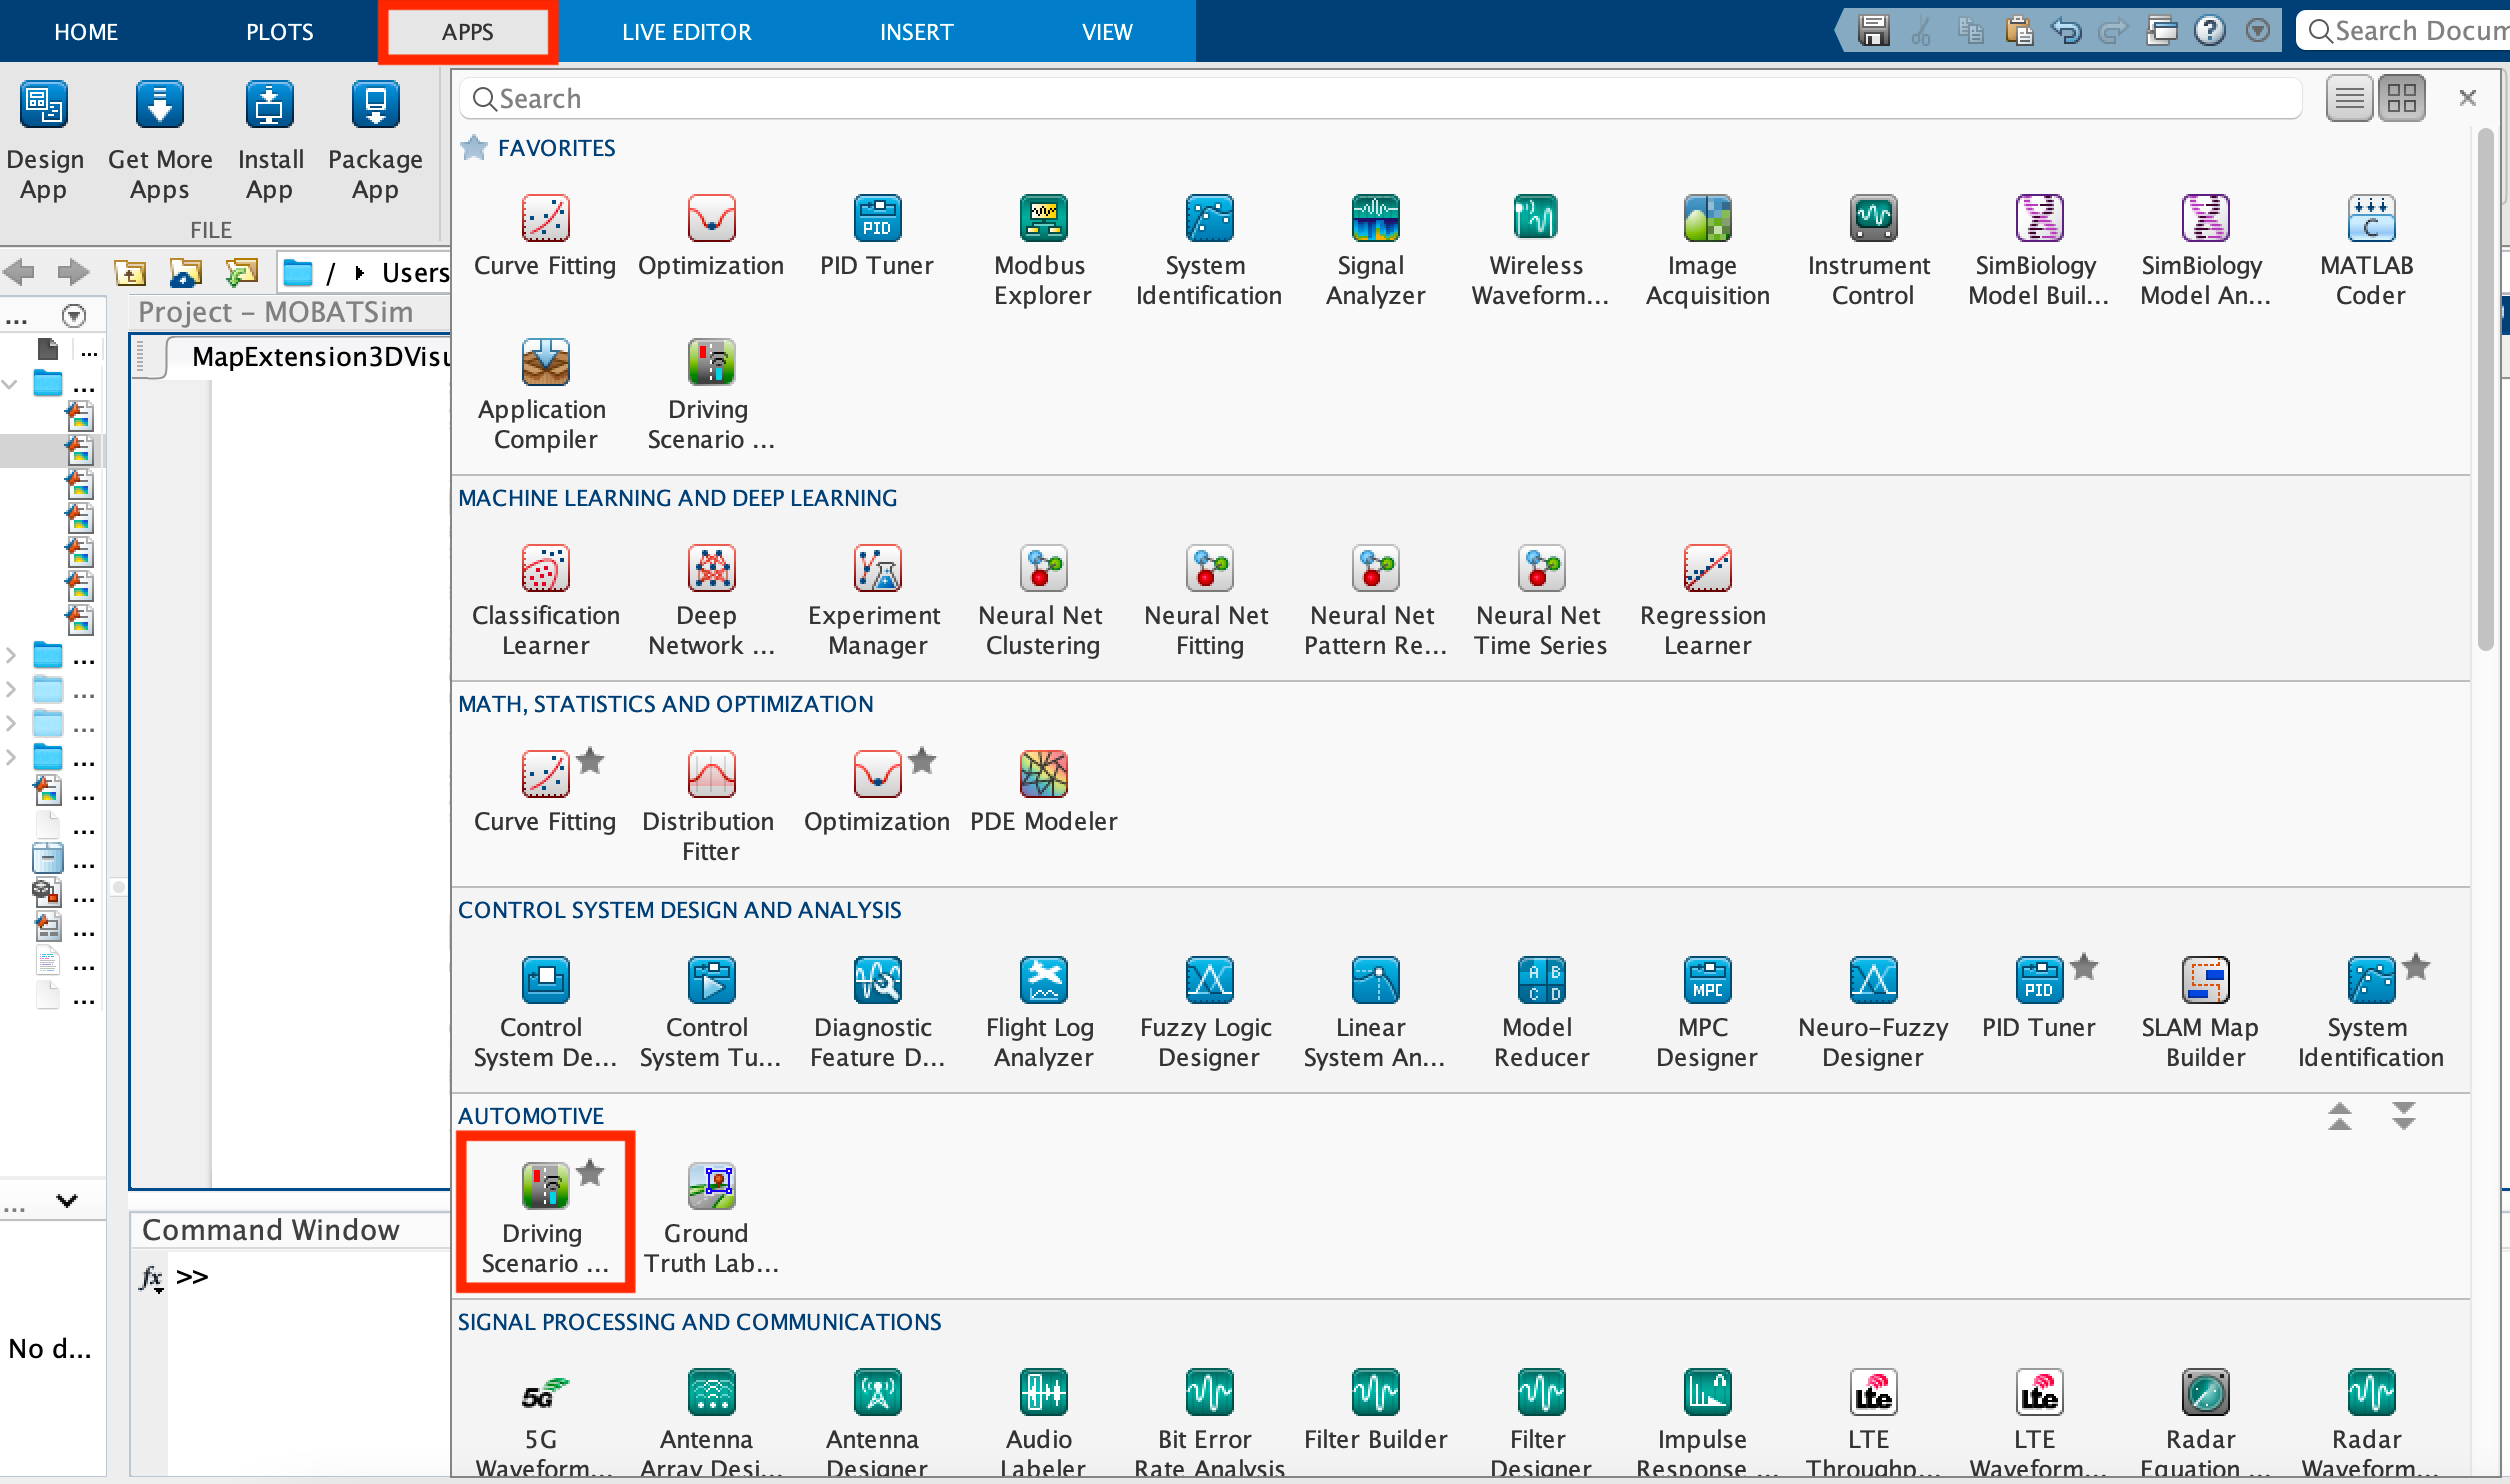

### Loading the MOBATSim Map

The Mobatkent map, the default map in MOBATSim, is redrawn in the Driving Scenario Designer App to fit it to the OPENDrive Format. Therefore to extend the Mobatkent map, you can simply load the relevant .mat file, which contains the road definitions in the Mobatkent map first.

**(2) **From the top left corner of the APP, click "Open"  and if you are running for the first time, choose the "Scenario File..." option to browse the .mat file from *"scr\Scripts\Load Data\map_v1\map_v1.mat"*  in the app. Later on, this option will appear on the bottom of the menu, as you see in the figure below.

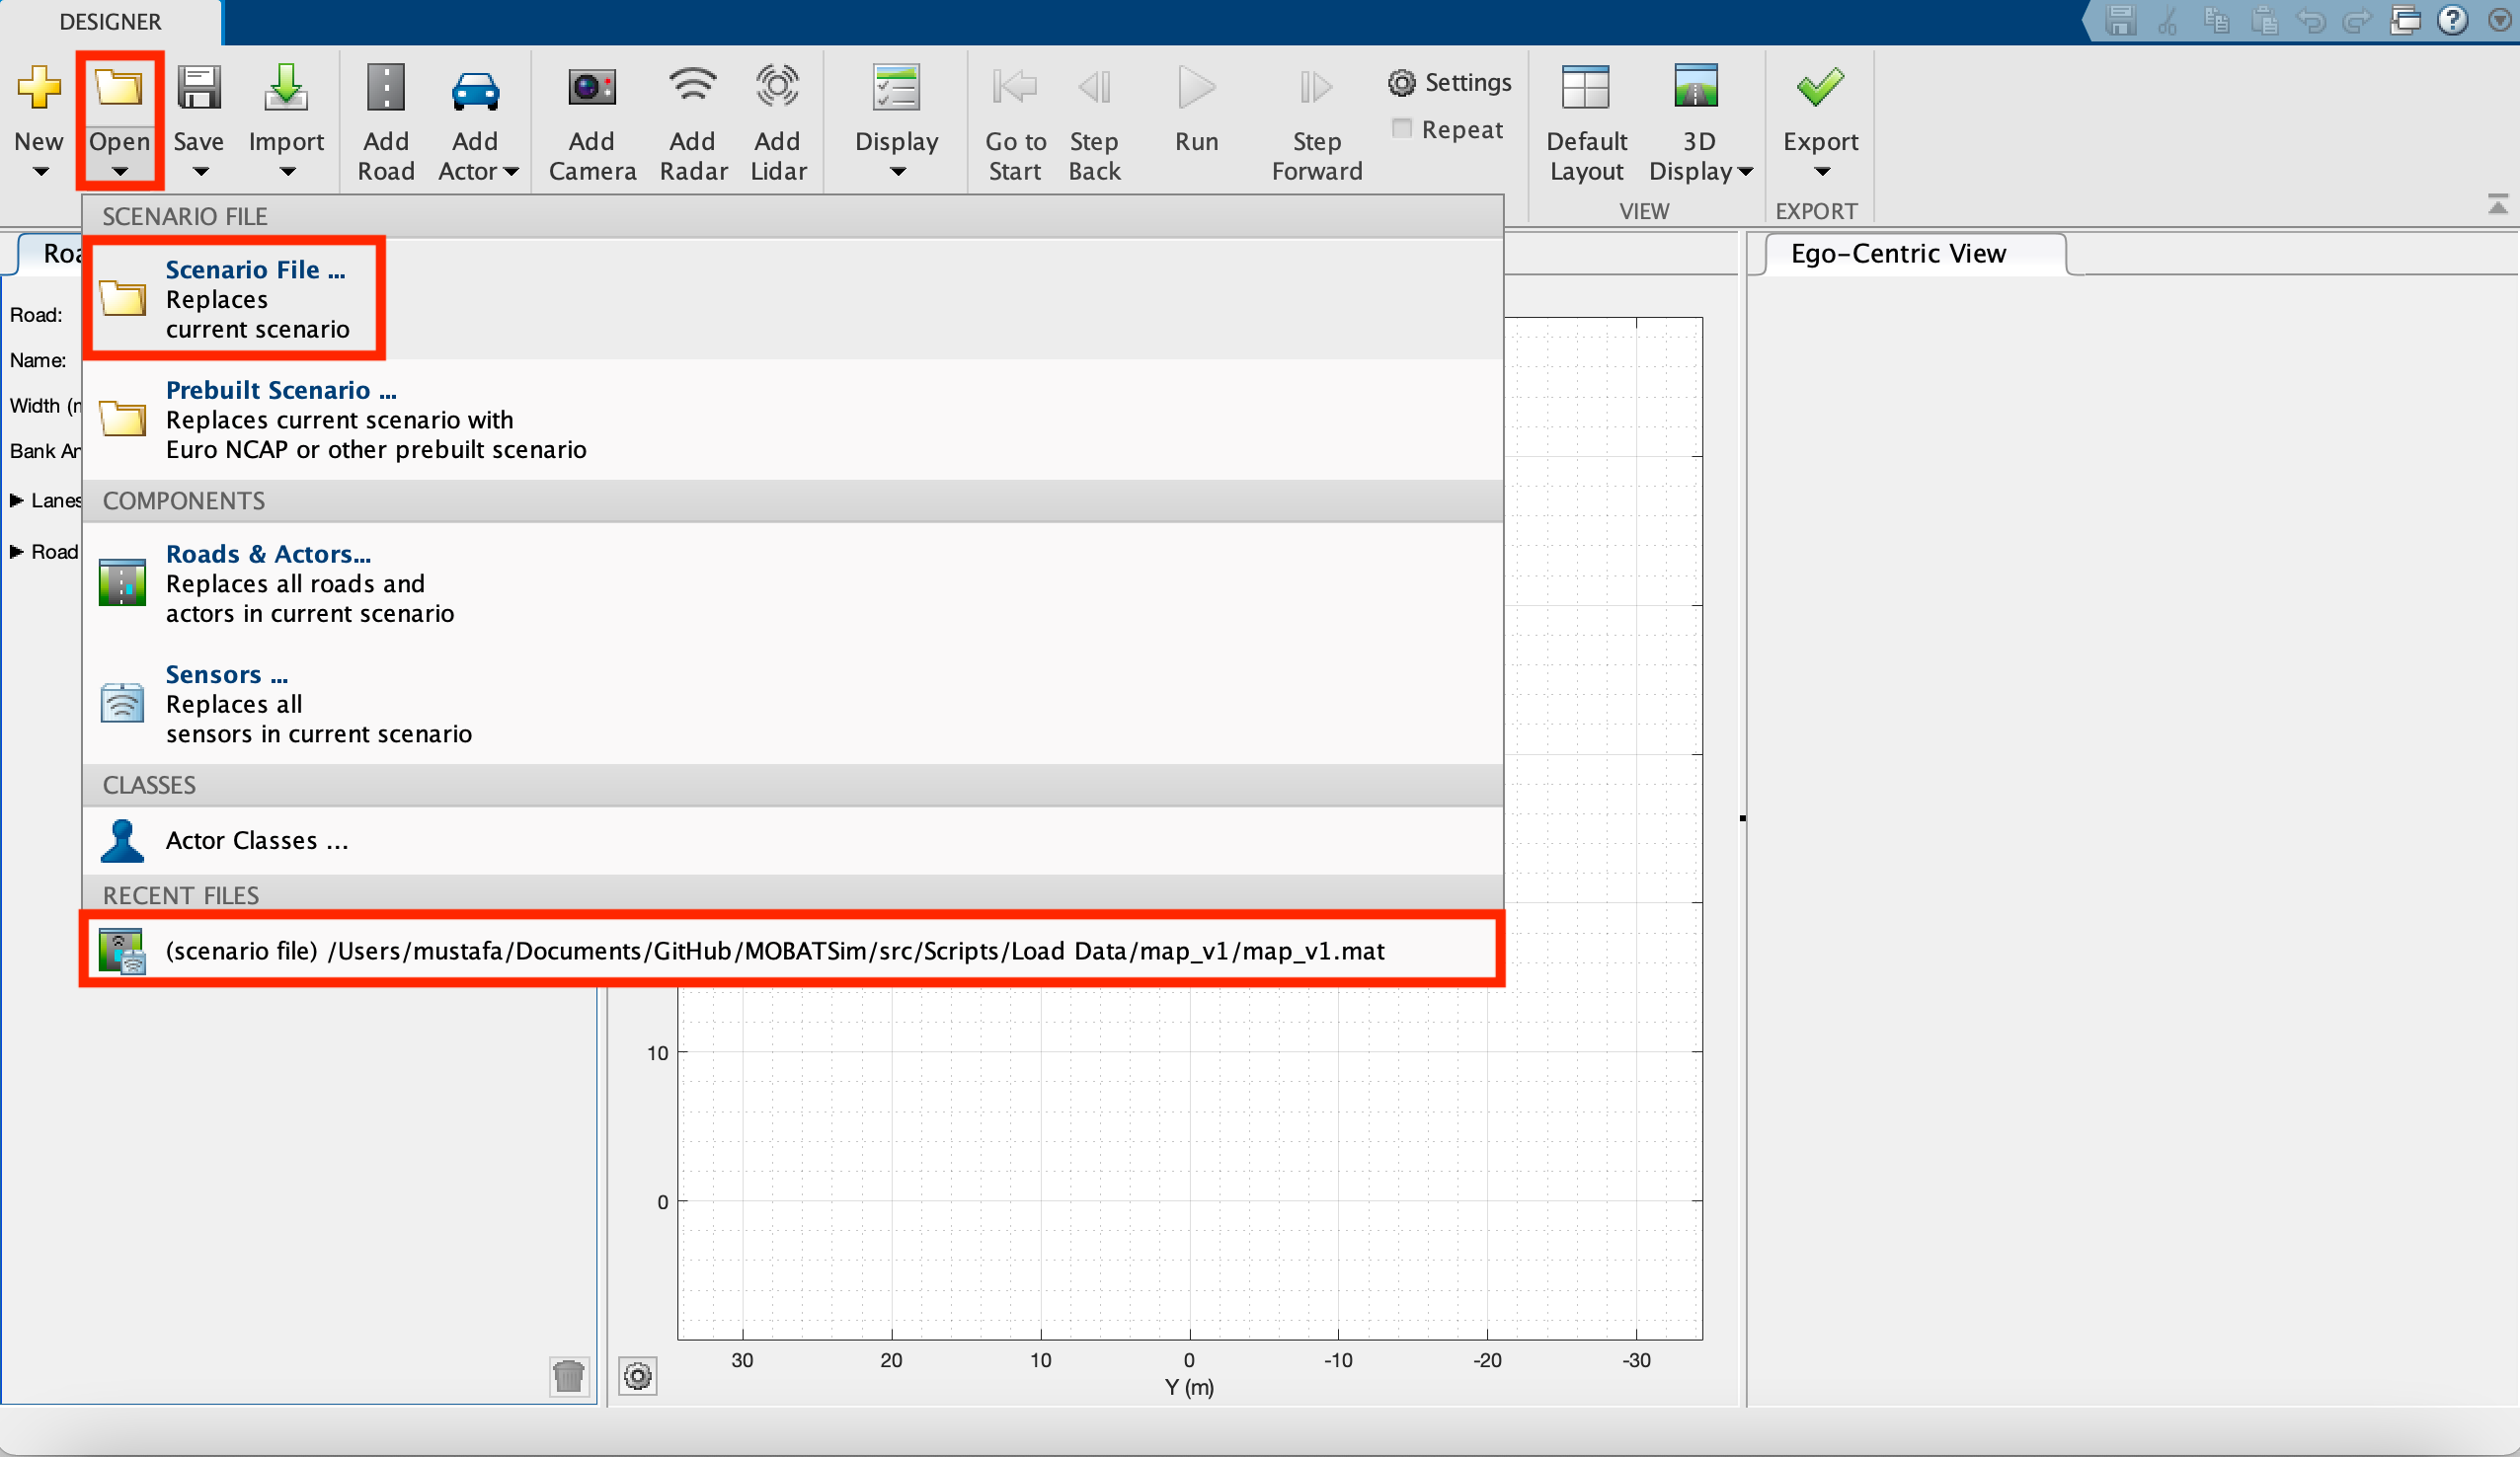

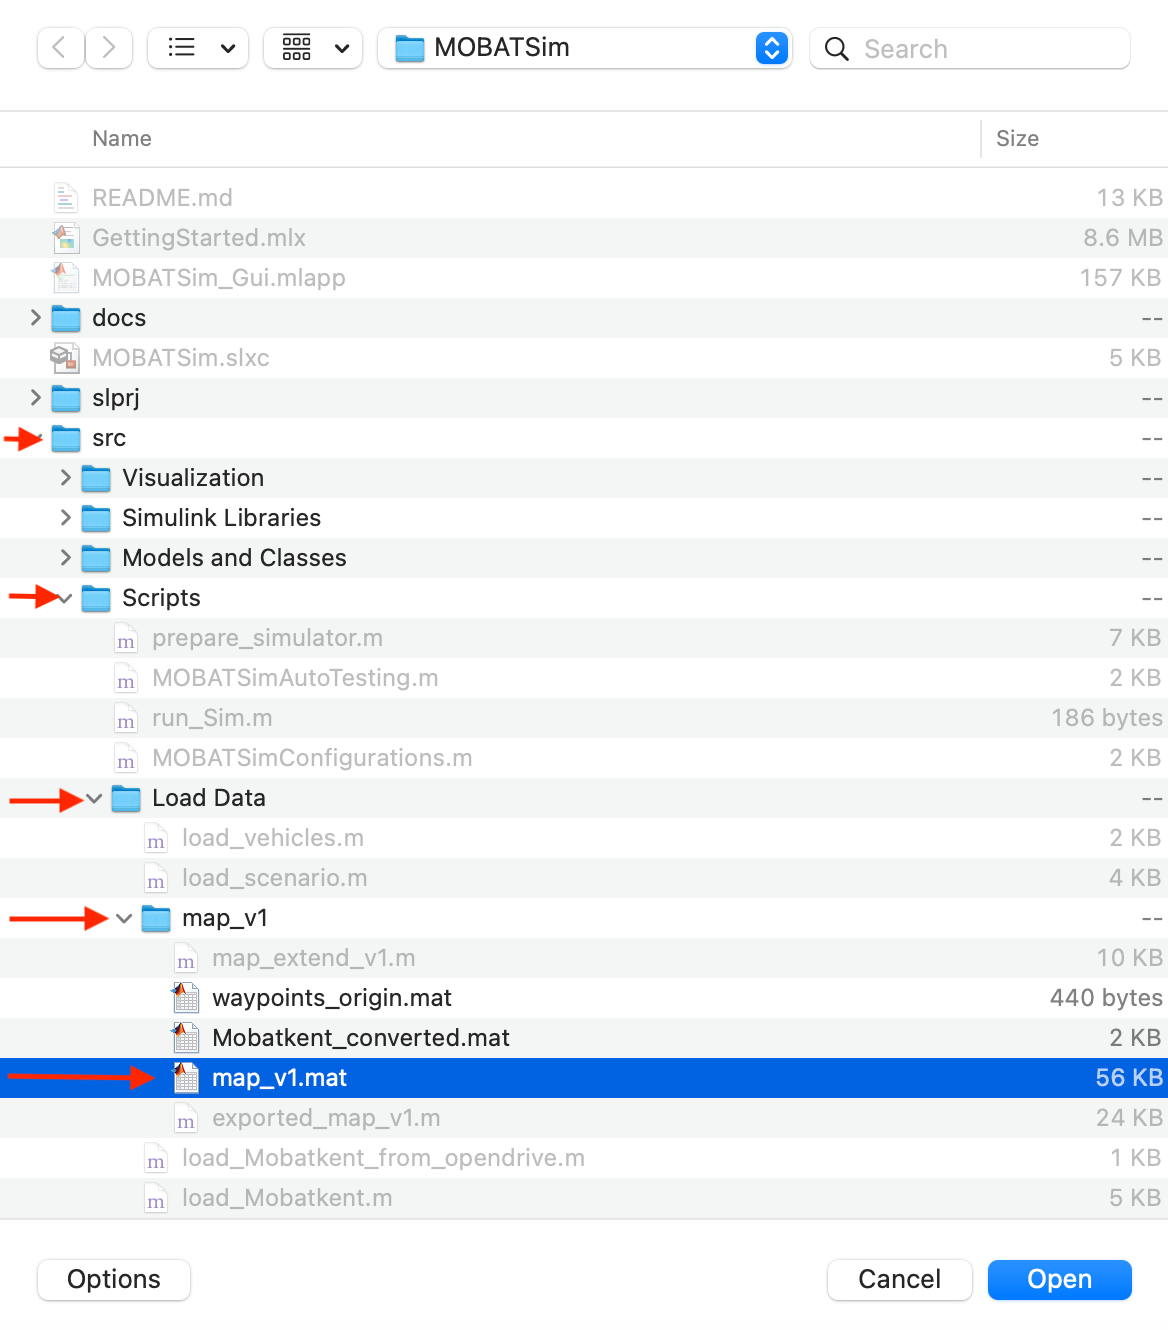

Once you load the map, you will see the road structure, defined waypoints, and intermediate waypoints defining the curved road segments.

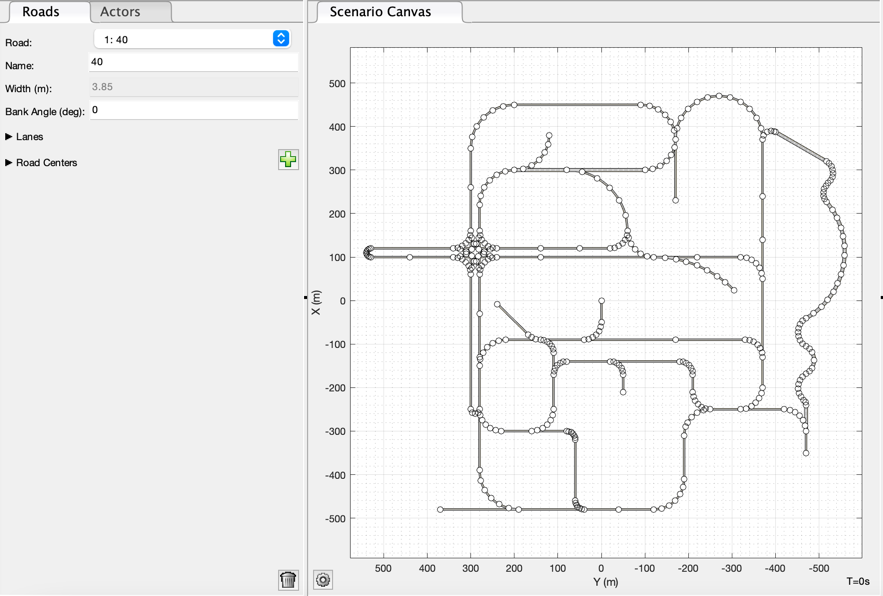

### Extending the MOBATSim Map

**(3)** The map can be extended by creating new road segments or changing the existing road segments' coordinates and lane numbers. One crucial thing to remember is that the road segments must have the exact same coordinates of end and starting points if the user wants to connect them. This allows the conversion algorithm from OPENDrive to MOBATSim to recognize the connectivity of these road segments.

One other point to keep in mind is that Bezier curves are used to define curved roads in the Driving Scenario Designer App; however, in MOBATSim, curved roads are defined by circular arc segments with the same curvature along the arc. Hence, an exact approximation is theoretically impossible without defining an infinite number of points for each curved road segment. However, depending on the length of the curved road segment, to approximate a circular arc as closely as possible, the number of intermediate points should be more than five.

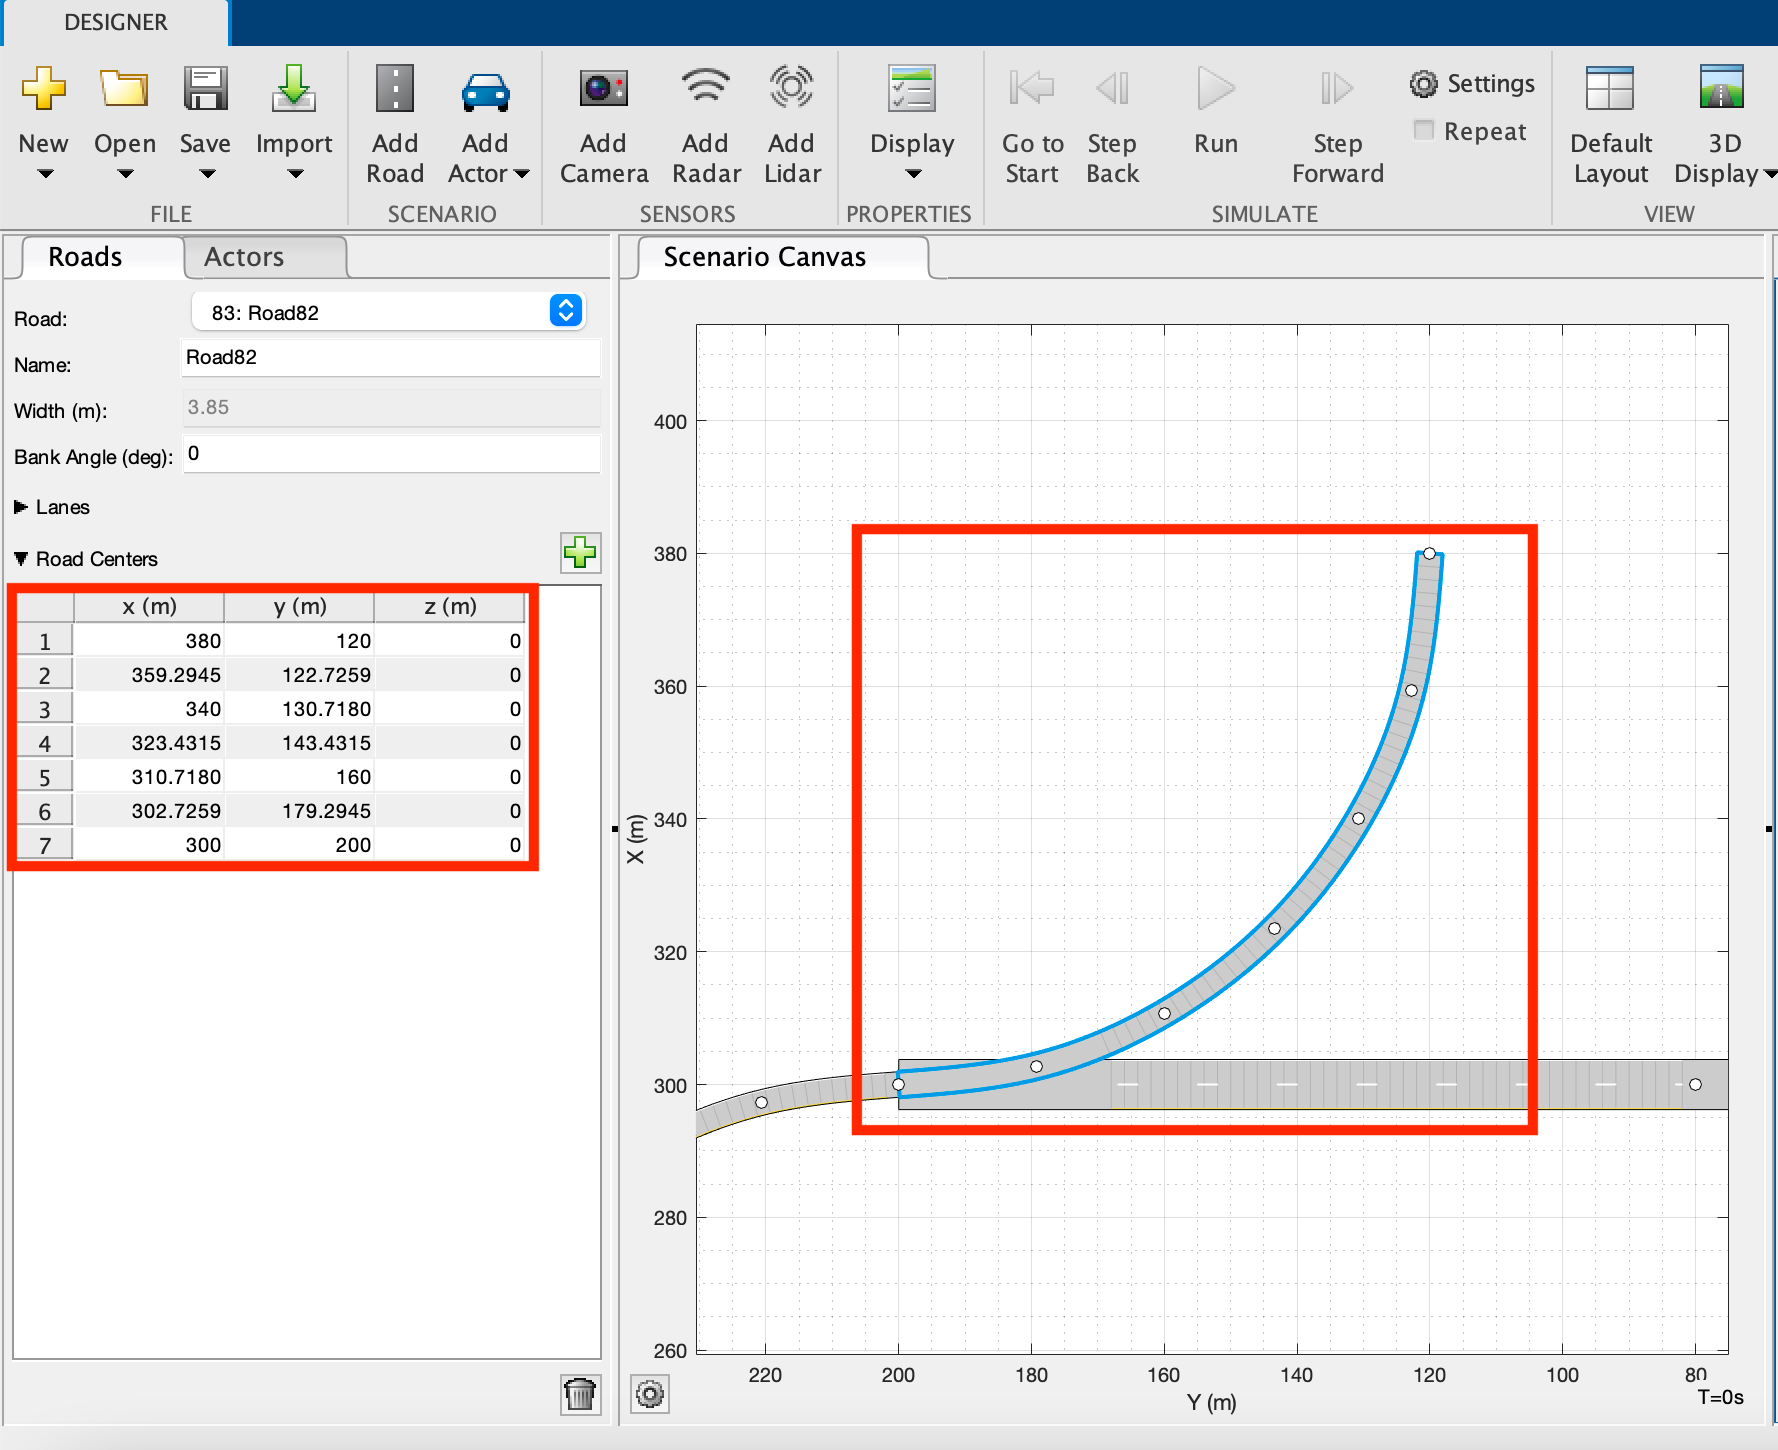

If you want to change a road segment from a single lane to a double lane, just change the **Number of Lanes** from **1** to **2**.

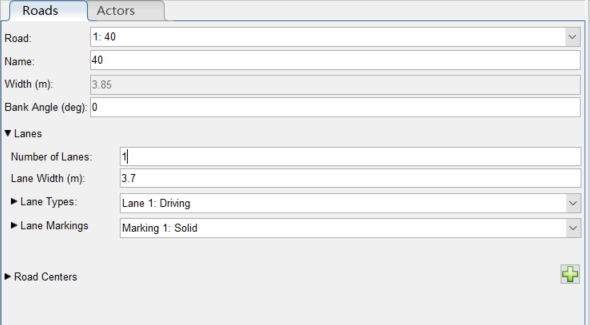

**(4) **This data file should be saved as a .mat file after extending it from the drivingScenarioDesigner. This ensures that we can keep extending it in the future using the new .mat file. If you are sure about the changes, you can also overwrite the previous .mat file that we opened from the App.

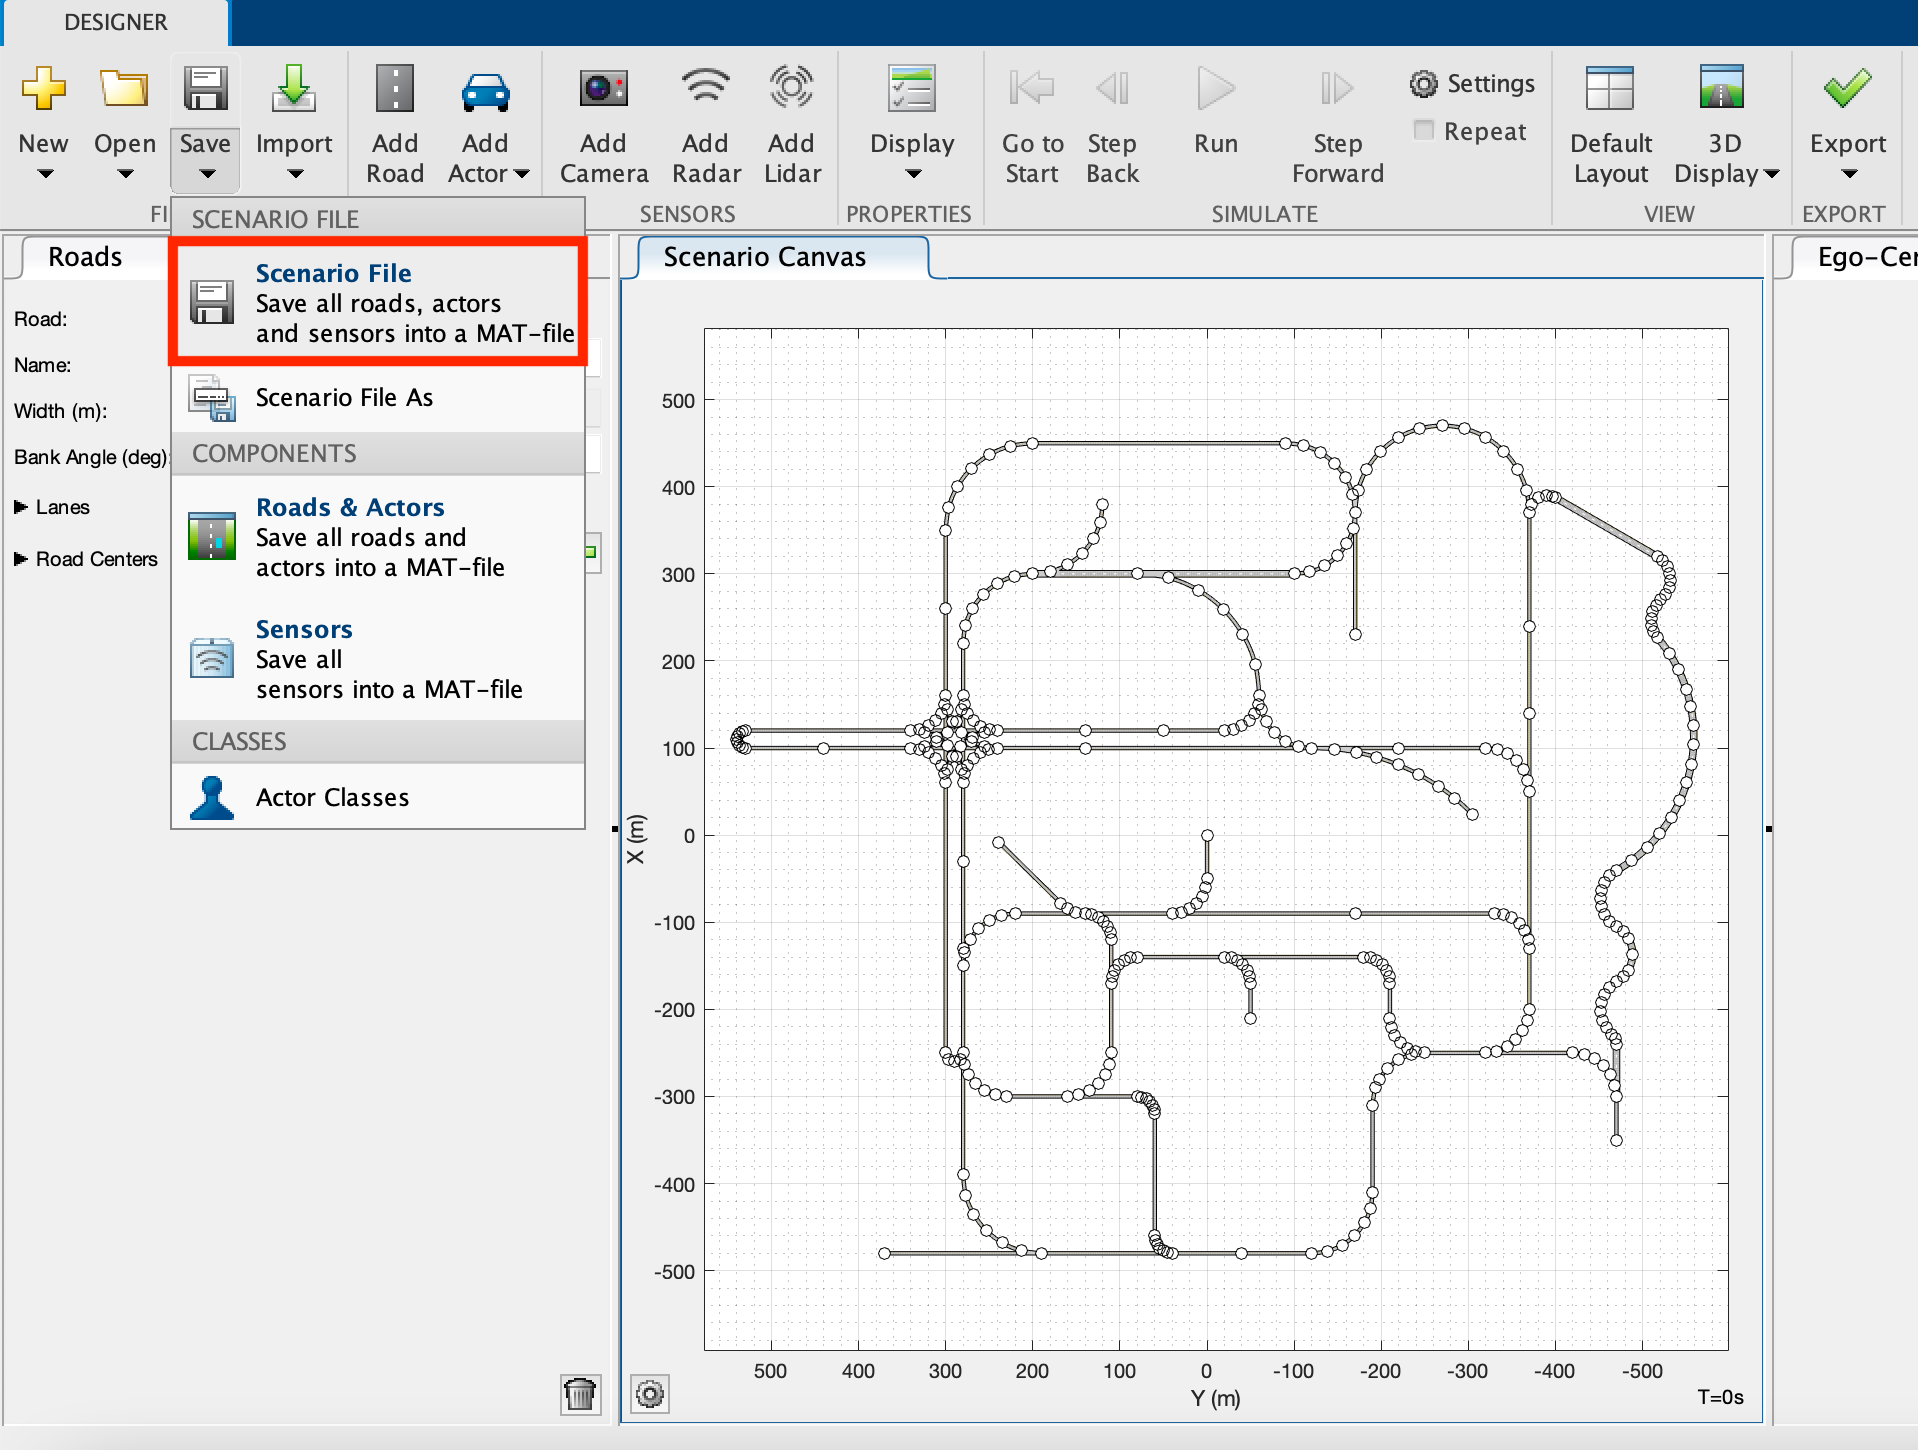

### Saving the MOBATSim Map as a Scenario File

**(5)** Click "*Export*", and click "*MATLAB Function*". This generates an m file that contains all the road structure data as an automatically generated code. Later on, this code will be used to generate the road structure for the **Bird's Eye View** or the **Unreal Engine** simulation.

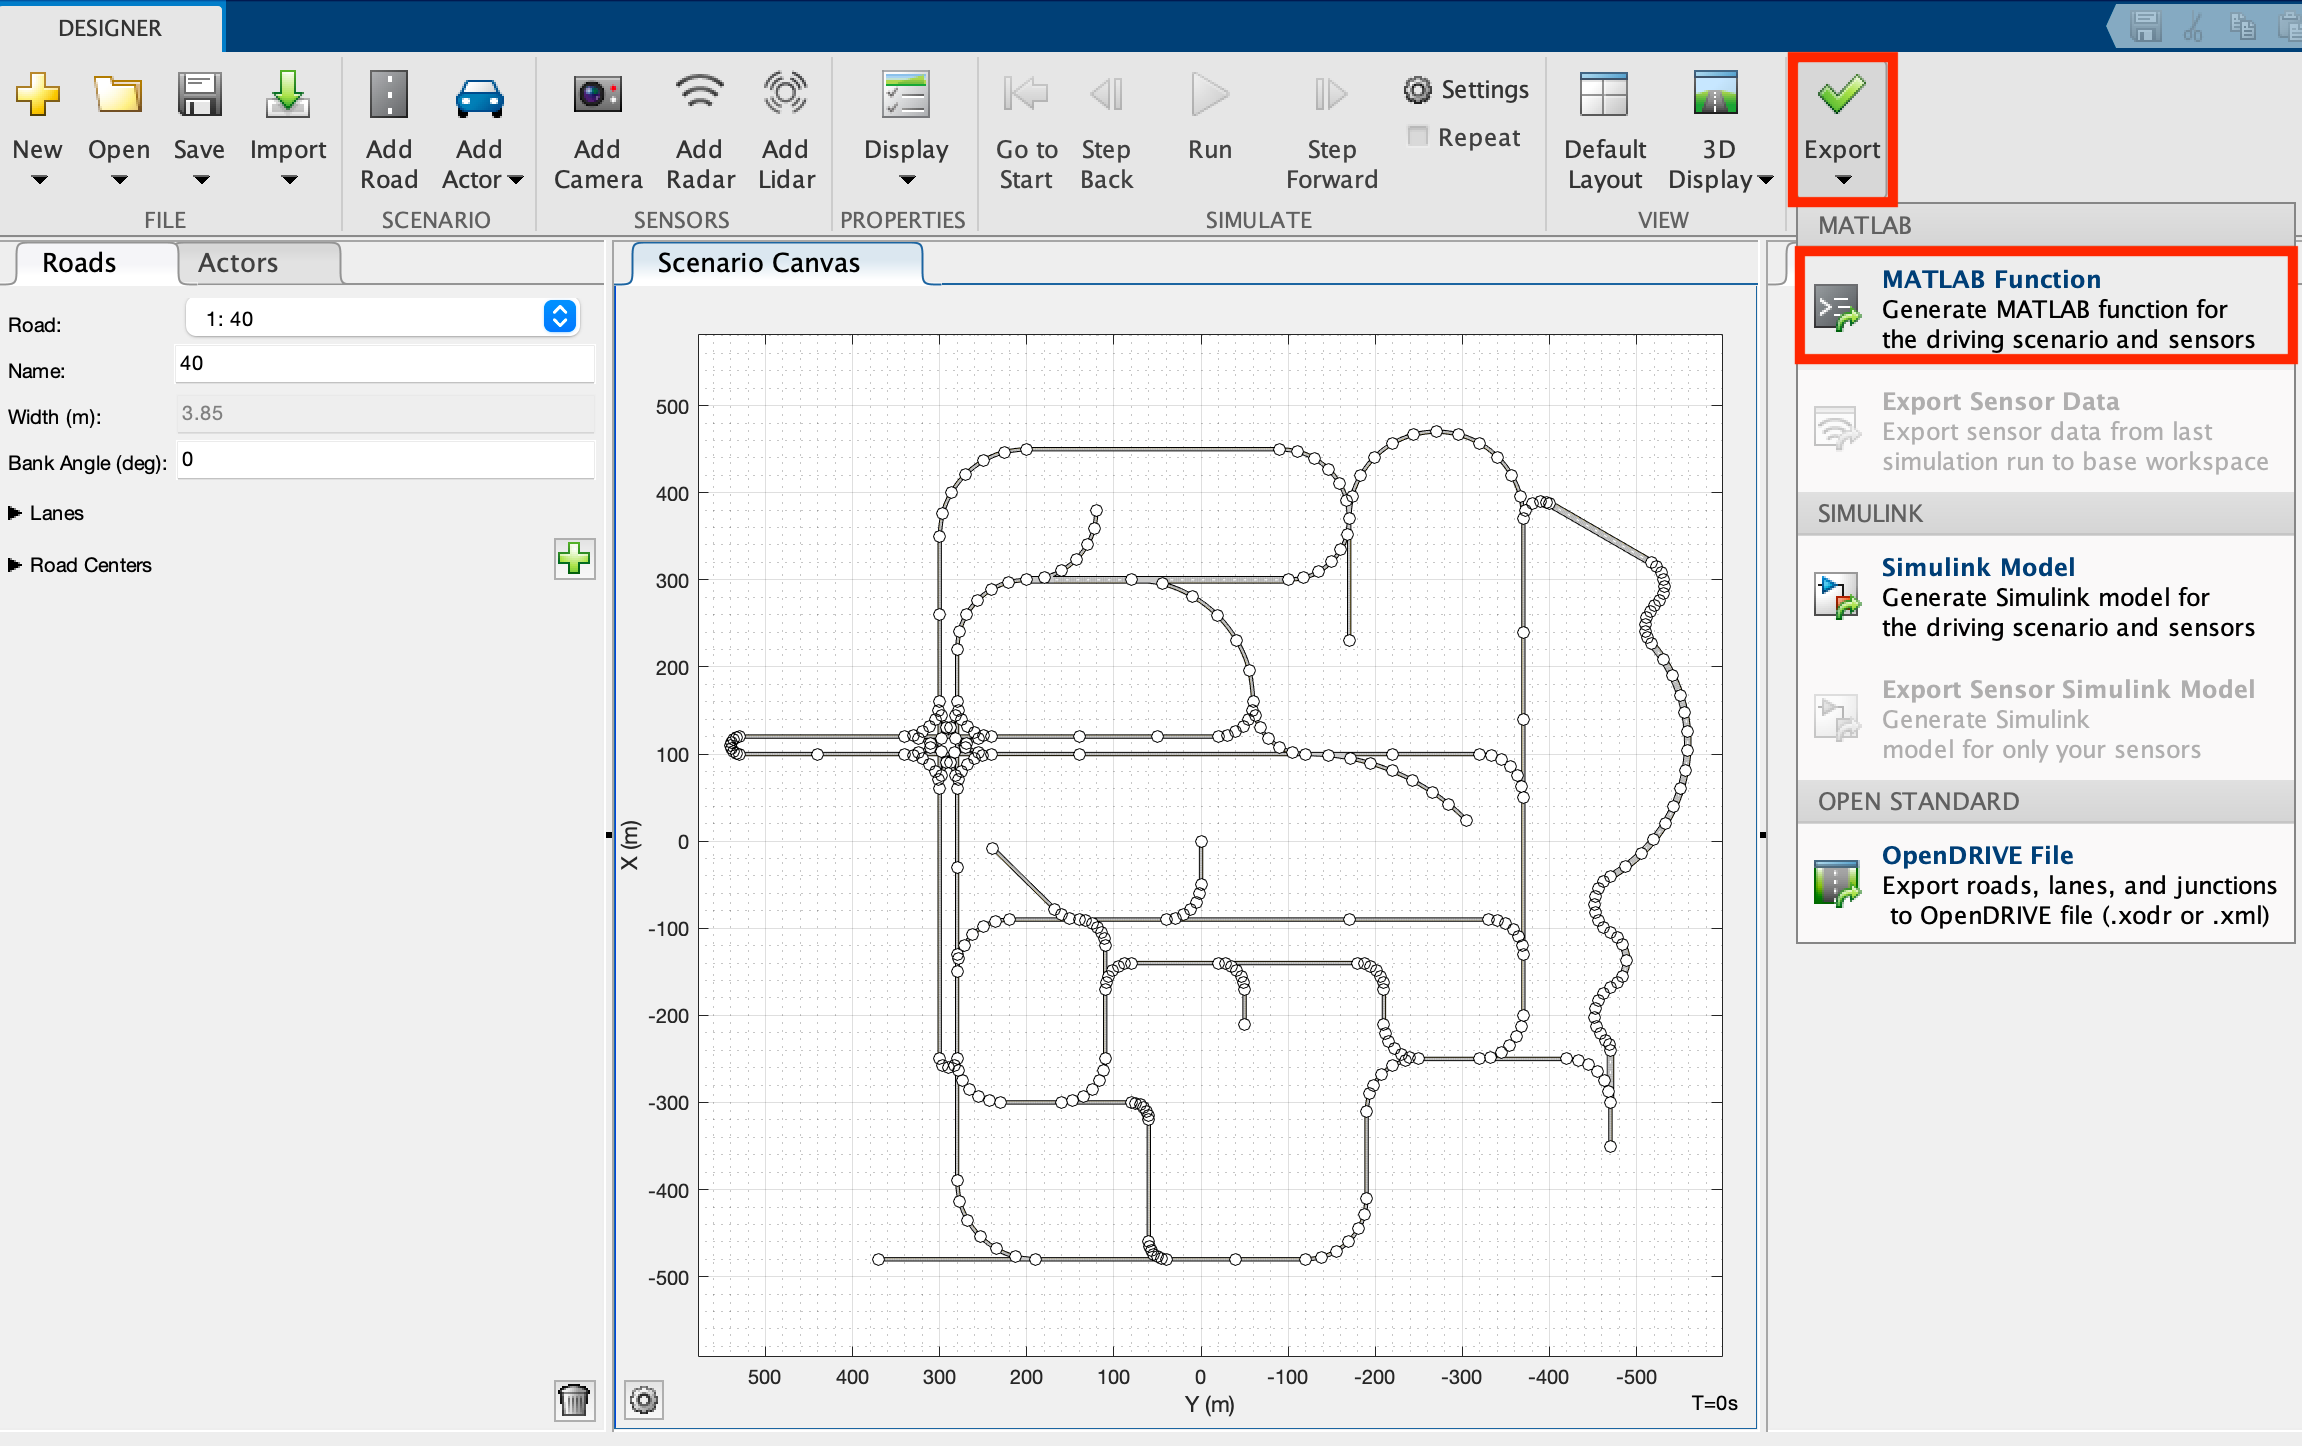

The exported function of the scenario contains the data of the map for visualization.

Save the function in folder *src/Scripts/Load Data/map_v1* as a `.m` file *map_v1.m*, and change the function's name to the same name with the function file.

If one of the roads needs to be shifted, change the coordinate of the corresponding `roadCenters`. This change is only for visualization; it does not change the MOBATSim map functionally.

The map is loaded in "*run_Bird_eye_view.m*" and "*openScenarioInApp.m*" for 2D and 3D visualization with following.

If the map is newly updated or changes, repeat the above procedure to update the scenario for visualization.

## Loading the Map in MOBATSim from a Scenario File

Since the map has been changed, the map must be converted to the MOBATSim structure from the `drivingScenarioDesigner` file. The sequence of the waypoints might be different, and this is especially important since the intersection waypoints are hard-coded according to their id numbers. So we will need to put them into the correct sequence in the conversion algorithm so that the extension waypoints start after the original Mobatkent map waypoints.

This algorithm is mainly in *src/Scripts/Load Data/map_v1/map_extend_v1.m*.

These two *.mat* file is loaded in *src/Scripts/Load Data/map_v1/map_extend_v1.m*. If there is another version of the extended map, just change the *src/Scripts/Load Data/map_v1/map_v1.mat* to another one.

First, load the data file, which includes the coordinates of several points of each road section.

Initialize the array for road information which is the same form as [../src/Scripts/Load Data/load_Mobatkent.m](matlab:open('..\src\Scripts\Load Data\load_Mobatkent.m')).

Next, according to the information of the above two loaded data files, the algorithm transforms the coordinates of the points to the format that we need. Detailed comments on the code can be found in [../src/Scripts/Load Data/map_v1/map_extend_v1.m](matlab:open('..\src\Scripts\Load Data\map_v1\map_extend_v1.m'))*.*

### Coordinate Transformation - OPENDrive to MOBATSim

The detailed workflow of the coordinate transformation algorithms can be found as comments in the relevant scripts.

### Coordinate Transformation - MOBATSim to OPENDrive

To get the lane numbers, we need to check them algorithmically from the Driving Scenario Designer file. In a future release, the lane numbers might be added to the MOBATSim Map data structure.

All the required information for the simulation to run has been loaded and available for plotting, pathfinding algorithms, and vehicles in MOBATSim. The helper functions required to realize the above tasks are explained in detail below.

### Helper Functions

There are four helper functions used in *src/Scripts/Load Data/map_v1/map_extend_v1.m*:

#### 1- `convertBackToMOBATSimfromAPP`

Outputs road edges as an array. Calculating the rotation center for the curved road is an essential part of this function:

The angle is calculated in Polar coordinates $\alpha =\theta_2 -\theta_1$.

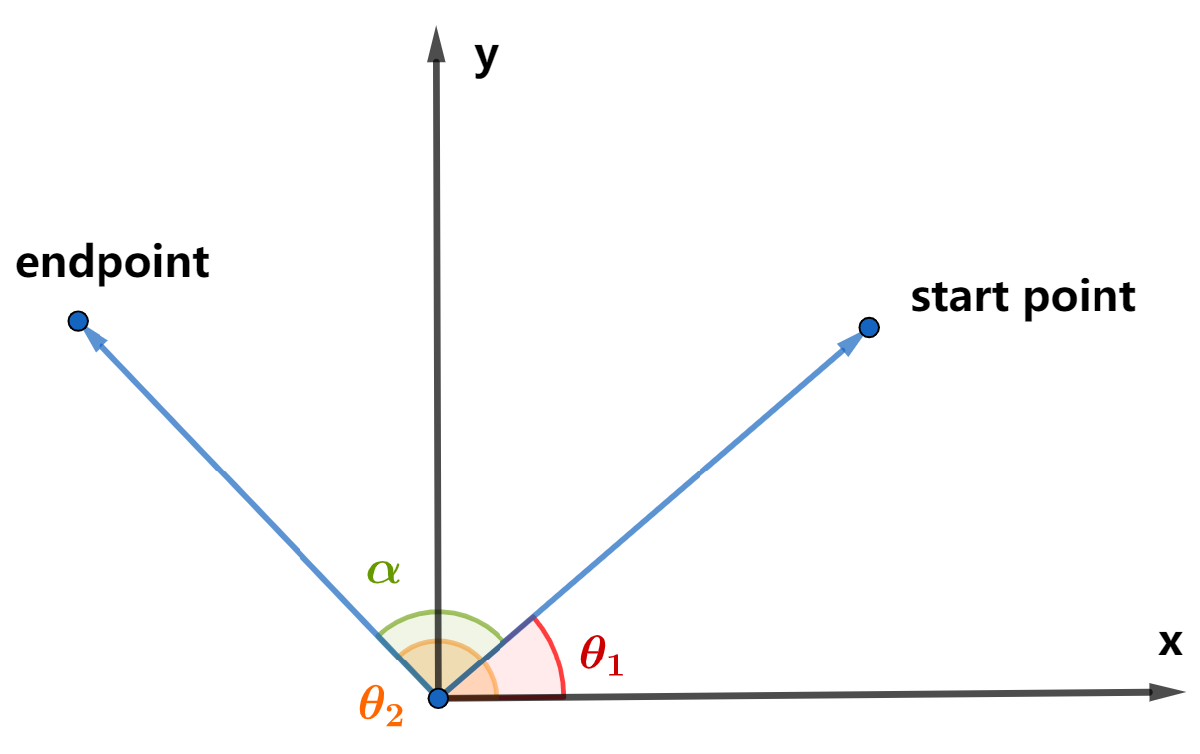

The angle is calculated in `drivingScenarioDesigner` coordinate, but in MOBATSim, the range of angle is $\left\lbrack -\pi ,\pi \right\rbrack$, so we should make sure that the result is not outside of the range.

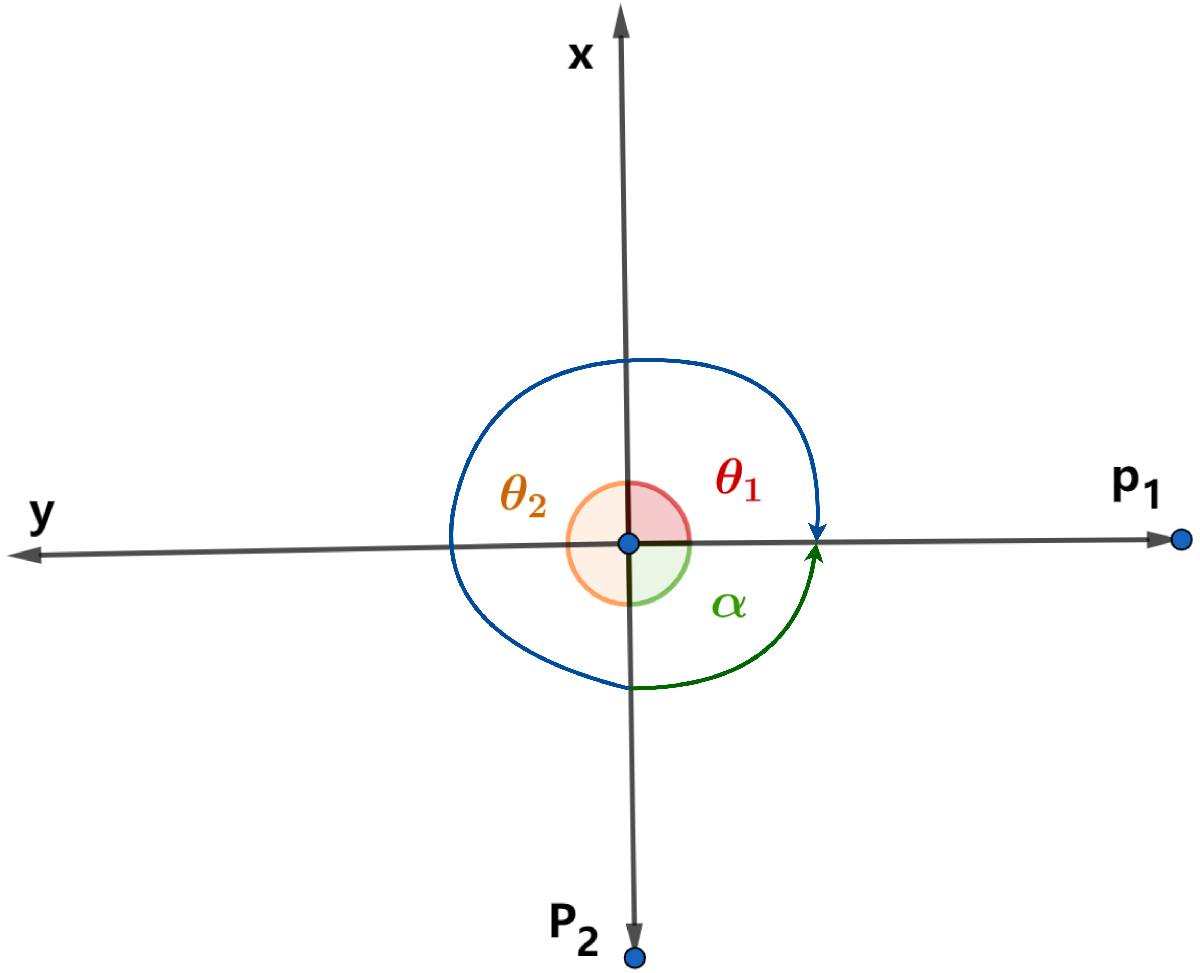

In the figure above, $p_2$ is the starting point, $p_1$ is the endpoint, the angle is counterclockwise. In `drivingScenarioDesigner` coordinates, $\theta_2 =\pi$, $\theta_1 =-\frac{\pi }{2}$, $\alpha =\theta_2 -\theta_1 =\frac{-3\pi }{2}$ , which is outside of the range. So $2\pi$ is added and the final result is: $\alpha =\alpha +2\pi =\frac{\pi }{2}$.

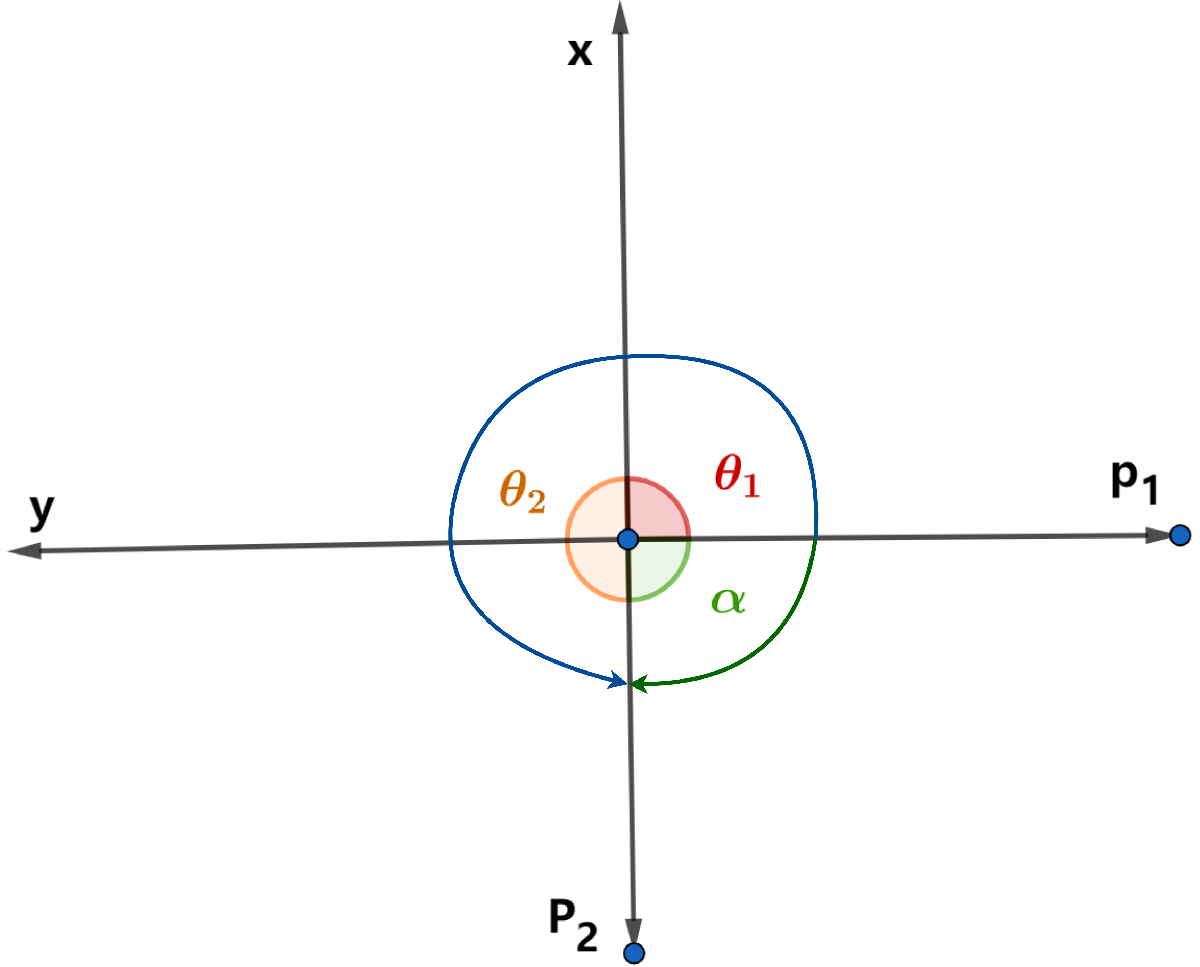

In the figure above, $p_1$ is the start point, $p_2$ is the endpoint, the direction of the rotation is clockwise. In the drivingScenarioDesigner coordinate system, $\theta_2 =\pi$, $\theta_1 =\frac{-\pi }{2}$, $\alpha =\theta_2 -\theta_1 =\frac{3\pi }{2}$, which is not in the range. So $2\pi$ subtracted and the final result is: $\alpha =\alpha -2\pi =\frac{-\pi }{2}$.

#### 2- Circle_center

This function calculates the rotation center of the curved road section, which is used in the first function.

#### 3- Order_sequence

This function puts the points of the extended map into the same order as the original map. Therefore, the new waypoints of the extended road segments start with the numbers defined after the old map's waypoints. This makes sure that the consistency of the previous map is preserved regarding the intersection waypoints.

#### 4- Route_LaneNumber

This function finds the number of lanes for the corresponding road.

The workflow of this function is shown below:

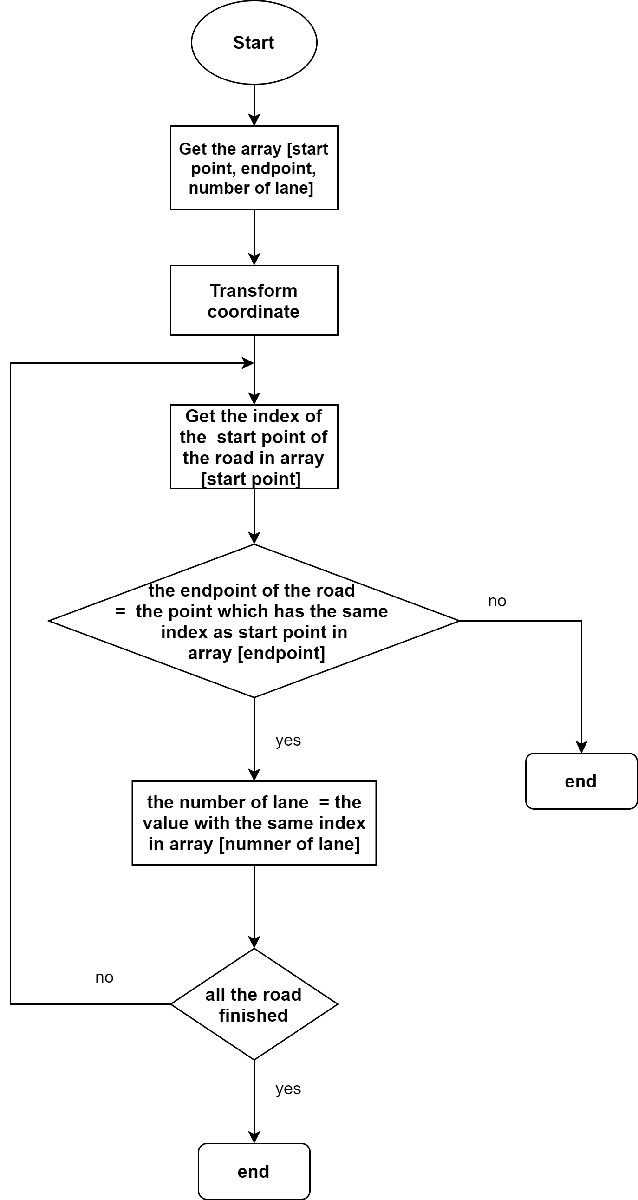

For other details in this algorithm, you can check the comments of the function "[map_extend_v1.m](matlab:open('..\src\Scripts\Load Data\map_v1\map_extend_v1.m'))".

If you just run "*map_v1/map_extend_v1.m*", there are four output arrays:

When you make some changes, do not forget to check if the above output is correct.

The final output of the *src/Scripts/Load Data/map_v1/map_extend_v1.m* is the form shows below:

Next, just add the below line in *src/Scripts/Load Data\load_Mobatkent_from_opendrive.m*

Next, load the extended map in the load map section in *src/Scripts/prepare_simulator.m* instead of the original one.

Finally, run "*prepare_simulator.m*", you can get the map in the simulation.

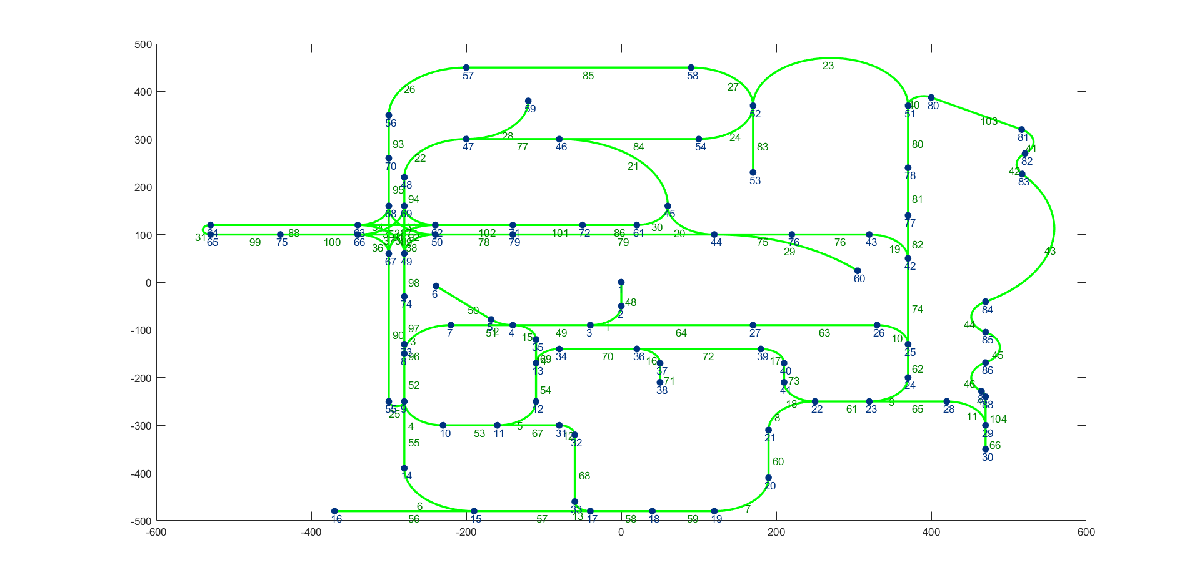

# III. MOBATSim - OpenDRIVE Compatibility

An automatic algorithm for converting the **MOBATSim Map directly into** **OPENDrive format** will be developed soon. Currently, the MOBATSim Map is redrawn in the **Driving Scenario Designer App**, and it is saved after every extension, as explained above.

Using straight roads and curved roads with different lengths and angles make it possible to define the MOBATSim map completely, allowing vehicles to reach every waypoint. The overlapping between routes is only permitted on the intersections in the Mobatkent map, but crossing roads can be defined arbitrarily without any intersection manager. The structure of the Mobatkent map is contained as arrays in the `load_map` function along with the crossroad nodes, which are controlled by an autonomous intersection manager (will be explained in another documentation). 

With the new Driving Scenario App extension, the previous data that was stored statically can also be generated in OpenDRIVE format using the App and then transformed into the MOBATSim structure. One new feature that is added with the extension is the double lanes. This information is kept for each route as either a single or double lane.

### Structural Differences and Possible Visualization Issues

The DrivingScenarioDesigner App uses [Bezier curves](https://en.wikipedia.org/wiki/B%C3%A9zier_curve) to generate the 2D map on the APP window. Since the Bezier curves do not have the same curvature properties as the circles, it is theoretically impossible to define a circle using a Bezier curve. Therefore, the exact locations of some intermediate points between the starting point and the endpoint of the road segment have to be entered in the DrivingScenarioDesigner APP to increase the accuracy. Depending on the length of the road, at least seven intermediate points are used to create the road segment with enough accuracy. The starting and endpoints should also have a very close adjacent point defined next to them to ensure that both ends of the road segment have the correct slope. Otherwise, some mismatch might occur at the ends of the road segments.